% 2.1 Operation between two matrices
A = [1 0 1; 2 3 4;-1 6 7];

B = [7 4 2; 3 5 6;-1 2 1];

a = A + B

a =      8     4     3
     5     8    10
    -2     8     8



b = A*B

b =      6     6     3
    19    31    26
     4    40    41



c = A*A

c =      0     6     8
     4    33    42
     4    60    72



d = A'

d =      1     2    -1
     0     3     6
     1     4     7



e = inv(B)

e =     0.1111    0.0000   -0.2222
    0.1429   -0.1429    0.5714
   -0.1746    0.2857   -0.3651



f = B' * A'

f =      6    19     4
     6    31    40
     3    26    41



g = A*A + B*B - A*B

g =     53    52    45
    15    51    58
    -2    28    42



h = [det(A), det(B), det(A*B)]

h =    12.0000  -63.0000 -756.0000


% 2.2 Determine Eigen values of matrices
A = [4 2 -3; -1 1 3;2 5 7];

B = [1 2 3; 8 7 6;2 5 7];

[V,D] = eig(A)

V =    -0.6713    0.9163   -0.3905
    0.6713   -0.3984    0.3905
   -0.3144    0.0398    0.8337


D =     0.5949         0         0
         0    3.0000         0
         0         0    8.4051



[W,E] = eig(B)

W =    0.2495 + 0.0000i   0.2824 - 0.1430i   0.2824 + 0.1430i
   0.7646 + 0.0000i  -0.7971 + 0.0000i  -0.7971 + 0.0000i
   0.5942 + 0.0000i   0.5051 + 0.0968i   0.5051 - 0.0968i


E =   14.2735 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.3632 + 0.7061i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.3632 - 0.7061i


% 2.3 Determine solution of system of equations
A = [0 1 -3; 2 3 -1; 4 5 -2];
b = [-5 7 10]';

X1 = inv(A)*b

X1 =    -1.0000
    4.0000
    3.0000


X2 = A\b

X2 =     -1
     4
     3


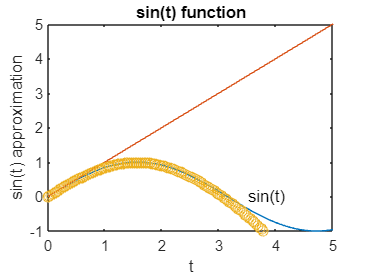

% 2.5 a i Generate plot for three functions
t = linspace(0,2*pi,200);
y1 = sin(t);
y2 = t;
y3 = t - (t.^3)/factorial(3) + (t.^5)/factorial(5) - (t.^7)/factorial(7);

% using plot command
figure(1)
plot(t,y1,t,y2,'-',t,y3,'o')
axis([0 5 -1 5])
xlabel('t');
ylabel('sin(t) approximation')
title('sin(t) function')
text(3.5, 0, 'sin(t)')

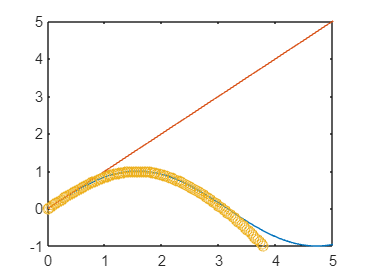

% 2.5 a ii using hold command
figure(2)
x = linspace(0,2*pi,200);
y1 = sin(x);
plot(x,y1);
hold on
y2 = x;
plot(x,y2,'-');
y3 = x - (x.^3)/factorial(3) + (x.^5)/factorial(5) - (x.^7)/factorial(7);
plot(x,y3,'o')
axis([0 5 -1 5])
hold off

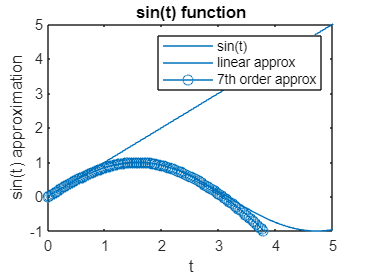

% 2.5 a iii using the line command
t = linspace(0,2*pi,200);
y1 = sin(t);
y2 = t;
y3 = t - (t.^3)/factorial(3) + (t.^5)/factorial(5) - (t.^7)/factorial(7);
plot(t,y1)
line(t,y2,'linestyle','-')
line(t,y3,'marker','o')
axis([0 5 -1 5])
xlabel('t');
ylabel('sin(t) approximation')
title('sin(t) function')
legend('sin(t)','linear approx','7th order approx')

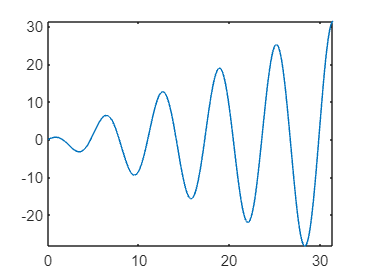

% 2.5 b i plot function using fplot
fplot(@(x)x.*cos(x),[0 10*pi])

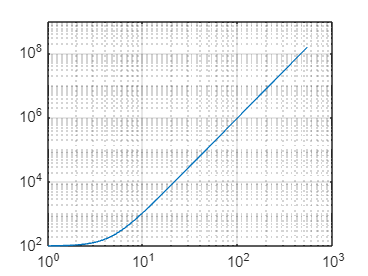

% 2.5 b ii plot a function using log scale
t = linspace(0, 2*pi,200);
x = exp(t);
y = 100 + exp(3*t);
loglog(x,y)
axis([1e0 1e3 1e2 1e9])
grid on

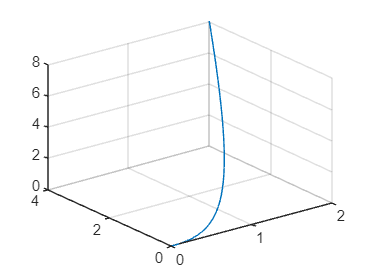

% 2.6 a Plot the parametric space curve
t = linspace(0, 2.0, 200);
x = t;
y = t.^2;
z = t.^3;
plot3(x,y,z);
axis([0 2 0 4 0 8])
grid on

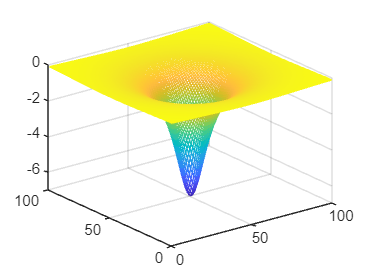

% 2.6 a Plot the parametric space curve
x = linspace(-5,5,100);
y = x;
z = zeros(length(x));
for i = 1:length(x)
    for j = 1:length(x)
         z(i,j) = -7/(1+ x(j)^2 + y(i)^2);
    end
end
mesh(z)

% 2.7 Polynom calculus
n = [1 6 5 4 3];
d = [1 7 6 5 4 7];

n2 = polyval(n,[-10 -5 -3 -1])

n2 =         4463         -17         -45          -1


d2 = polyval(d,[-10 -5 -3 -1])

d2 =       -35533         612         202           8



h = zeros(1,4);
for i = 1:4
    h(i) = n2(i)/d2(i);
end
h

h =    -0.1256   -0.0278   -0.2228   -0.1250


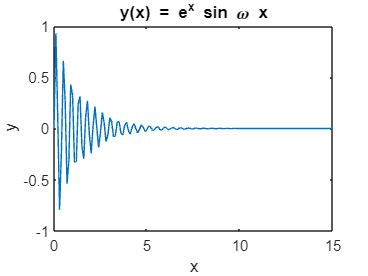

% 2.8 Generate a plot using colon notation to generate x
x = 0:0.1:15;
w = 15; %rad/s
y = exp(-0.7*x).*sin(w*x);
plot(x,y)
title('y(x) = e^-^0^.^7^x sin \omega x')
xlabel('x')
ylabel('y')

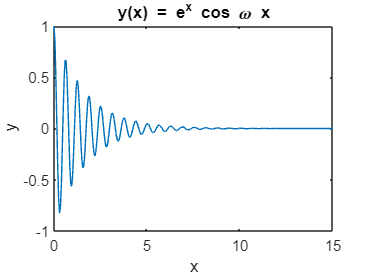

% 2.9 Generate a plot using colon notation
x = 0:0.05:15;
w = 10; %rad/s
y = exp(-0.6*x).*cos(w*x);
plot(x,y)
title('y(x) = e^-^0^.^6^x cos \omega x')
xlabel('x')
ylabel('y')

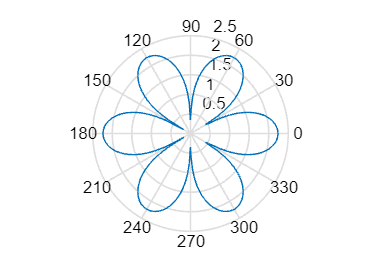

% 2.10 a plot polar
t = linspace(0,2*pi,200);
r = sqrt(abs(5*cos(3*t)));
polar(t,r)

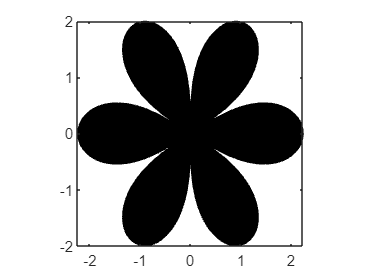

% 2.10 b plot fill x-y data
t = linspace(0,2*pi,200);
r = sqrt(abs(5*cos(3*t)));
x = r.*cos(t);
y = r.*sin(t);
fill(x,y,'k');
axis('square')

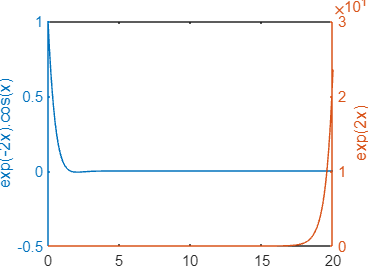

% 2.10 c plot y1 & y2 data
x = linspace(0,20,200);
y1 = exp(-2*x).*cos(x);
y2 = exp(2*x);
Ax = plotyy(x,y1,x,y2);
hy1 = get(Ax(1),'ylabel');
hy2 = get(Ax(2),'ylabel');
set(hy1, 'string', 'exp(-2x).cos(x)')
set(hy2, 'string', 'exp(2x)')

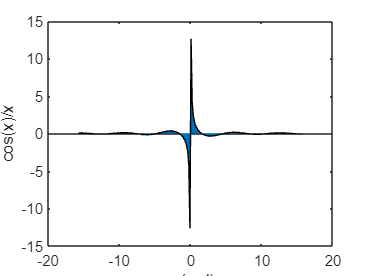

% 2.10 d plot area
x = linspace(-5*pi,5*pi,200);
y = cos(x)./x;
area(x,y);
xlabel('x (rad)');
ylabel('cos(x)/x');

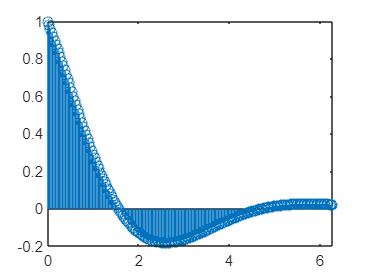

% 2.10 e plot stem
t = linspace(0,2*pi,200);
f = exp(-3*t/5).*cos(t);
stem(t,f)

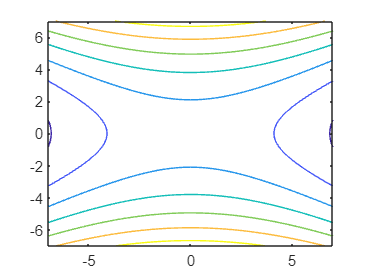

% 2.10 f plot contours
r = -7:0.2:7;
[X,Y] = meshgrid(r,r);
Z = -(1/3) * X.^2 + 2 * X * Y + Y.^2;
cs = contour(X,Y,Z);
xlabel(cs)

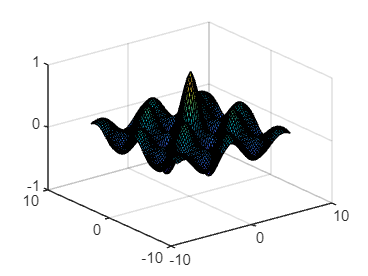

% 2.11 a plot surf
u = -7:0.2:7;
[X,Y] = meshgrid(u,u);
Z = cos(X) .* cos(Y) .* exp(-sqrt(X.^2 + Y.^2)/5);
surf(X,Y,Z);
axis([-10 10 -10 10 -1 1])

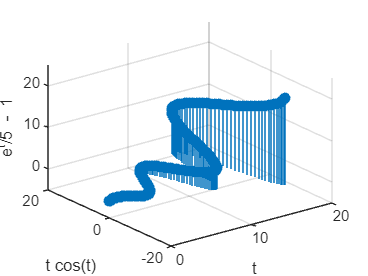

% 2.11 b plot stem3
t = linspace(0,5*pi,200);
x = t;
y = t.*cos(t);
z = exp(t/5) - 2;
stem3(x,y,z,'filled');
xlabel('t');
ylabel('t cos(t)');
zlabel('e^t/5 - 1');

axis([0 20 -20 20 -5 25])

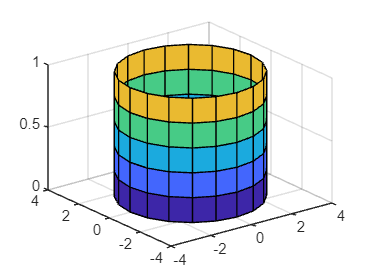

% 2.11 c plot cylinder
z = 0:0.2:1;
r = sin(5*pi*z)+3;
cylinder(r)

axis([-4 4 -4 4 0 1])

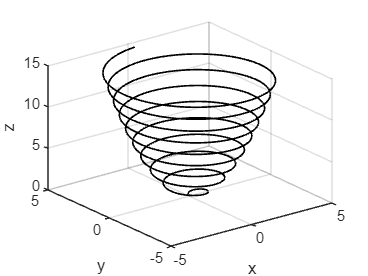

% 2.12 plot (x,y,z)
t = 0:0.01:6*pi;
x = sqrt(t).*sin(3*t);
y = sqrt(t).*cos(3*t);
z = 0.8*t;
plot3(x,y,z,'k','LineWidth',1)
grid on
xlabel('x');
ylabel('y');
zlabel('z');

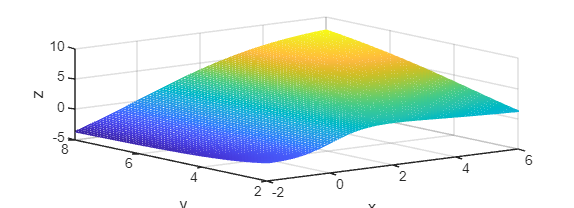

% 2.13 plot mesh and surface
x = -2:0.1:6;
y = 2:0.1:8;
[x,y] = meshgrid(x,y);
z = (2*x.*(y.^2))./((x.^2) + (y.^2));
mesh(x,y,z)
xlabel('x');
ylabel('y');
zlabel('z');

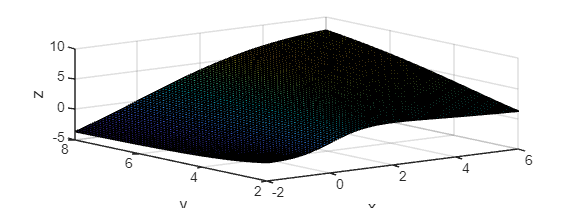


surf(x,y,z)
xlabel('x');
ylabel('y');
zlabel('z');

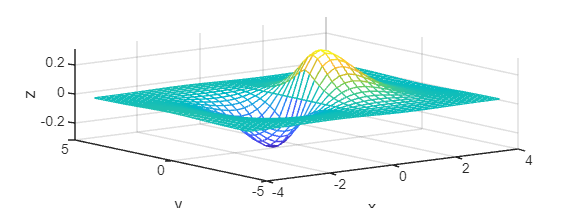

% 2.14 a plot mesh
x = -4:0.25:4;
y = -4:0.25:4;
[x,y] = meshgrid(x,y);
z = 2.^(-1.5*sqrt(x.^2 + y.^2)).*sin(x).*cos(0.5*y);
mesh(x,y,z)
xlabel('x');
ylabel('y');
zlabel('z');

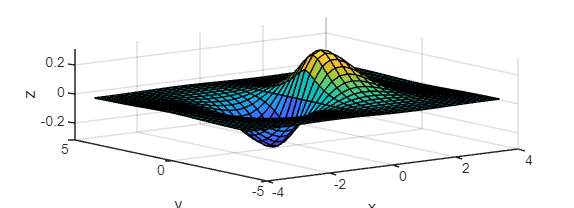

% 2.14 b plot surface
x = -4:0.25:4;
y = -4:0.25:4;
[x,y] = meshgrid(x,y);
z = 2.0.^(-1.5*sqrt(x.^2 + y.^2)).*sin(x).*cos(0.5*y);
surf(x,y,z)
xlabel('x');
ylabel('y');
zlabel('z');

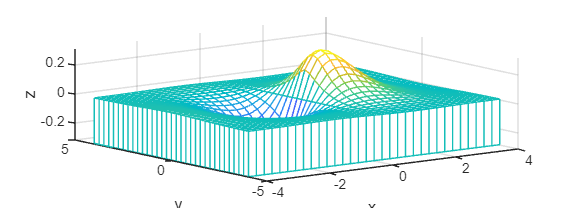

% 2.14 c mesh curtain plot
x = -4:0.25:4;
y = -4:0.25:4;
[x,y] = meshgrid(x,y);
z = 2.^(-1.5*sqrt(x.^2 + y.^2)).*sin(x).*cos(0.5*y);
meshz(x,y,z)
xlabel('x');
ylabel('y');
zlabel('z');

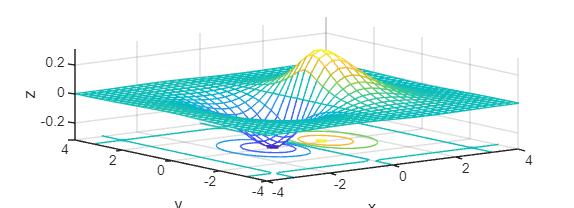

% 2.14 d mesh and contour
x = -4:0.25:4;
y = -4:0.25:4;
[x,y] = meshgrid(x,y);
z = 2.^(-1.5*sqrt(x.^2 + y.^2)).*sin(x).*cos(0.5*y);
meshc(x,y,z)
xlabel('x');
ylabel('y');
zlabel('z');

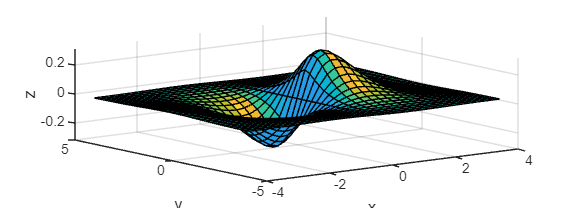

% 2.15 a surface plot with lighting
x = -4:0.25:4;
y = -4:0.25:4;
[x,y] = meshgrid(x,y);
z = 2.^(-1.5*sqrt(x.^2 + y.^2)).*sin(x).*cos(0.5*y);
surfl(x,y,z)
xlabel('x');
ylabel('y');
zlabel('z');

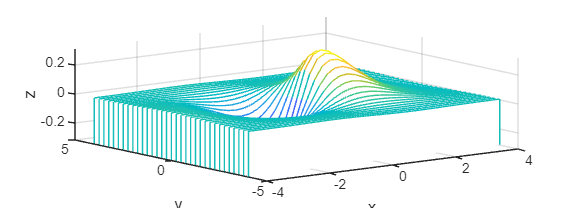

% 2.15 b waterfall plot
x = -4:0.25:4;
y = -4:0.25:4;
[x,y] = meshgrid(x,y);
z = 2.^(-1.5*sqrt(x.^2 + y.^2)).*sin(x).*cos(0.5*y);
waterfall(x,y,z)
xlabel('x');
ylabel('y');
zlabel('z');

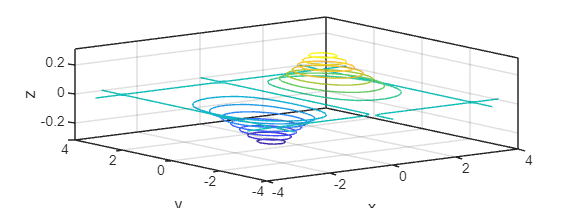

% 2.15 c 3D contour plot
x = -4:0.25:4;
y = -4:0.25:4;
[x,y] = meshgrid(x,y);
z = 2.^(-1.5*sqrt(x.^2 + y.^2)).*sin(x).*cos(0.5*y);
contour3(x,y,z,15)
xlabel('x');
ylabel('y');
zlabel('z');

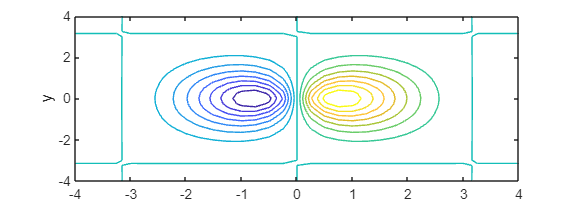

% 2.15 d 2D contour plot
x = -4:0.25:4;
y = -4:0.25:4;
[x,y] = meshgrid(x,y);
z = 2.^(-1.5*sqrt(x.^2 + y.^2)).*sin(x).*cos(0.5*y);
contour(x,y,z,15)
xlabel('x');
ylabel('y');
zlabel('z');

% 2.16 a plot a function
fplot(@(x) x.*cos(x),[0 10*pi])

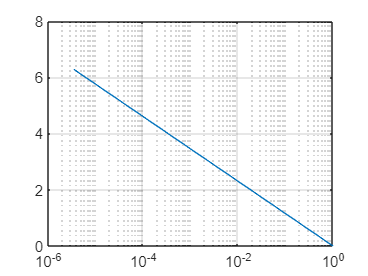

% 2.16 b plot a semi log function
t = linspace(0,2*pi,200);
x = exp(-2*t);
y = t;
semilogx(x,y);
grid
axis([1e-6 1 0 8])

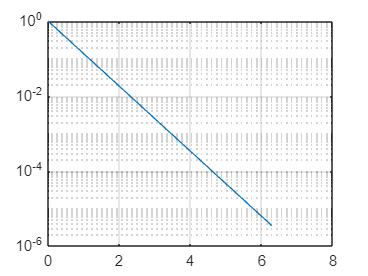

% 2.16 c plot a semi log function
t = linspace(0,2*pi,200);
x = exp(-2*t);
y = t;
semilogy(y,x);
grid
axis([0 8 1e-6 1])

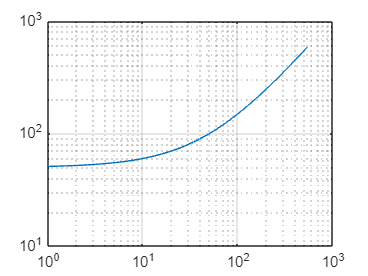

% 2.16 d plot a loglog function
t = linspace(0,2*pi,200);
x = exp(t);
y = 50 + exp(t);
loglog(x,y);
grid
axis([1 1e3 10 1e3])

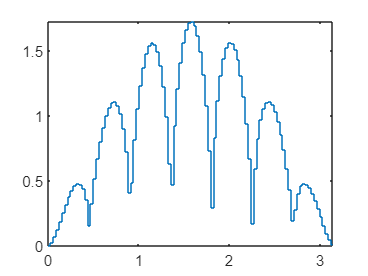

% 2.16 e plot a stairs function
t = linspace(0,2*pi,200);
y = sqrt(abs(3*sin(7*t))).*sin(t);
stairs(t,y);
axis([0 pi 0 inf])

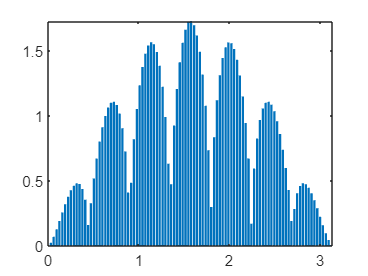

% 2.16 f plot a bar function
t = linspace(0,2*pi,200);
y = sqrt(abs(3*sin(7*t))).*sin(t);
bar(t,y);
axis([0 pi 0 inf])

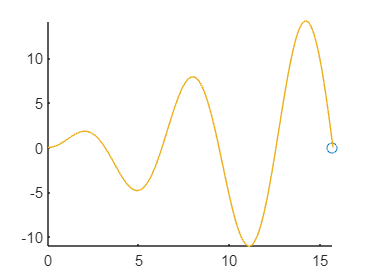

% 2.16 f plot a comet function
q = linspace(0,5*pi,200);
y = q.*sin(q);
comet(q,y);

% 2.17 Operation between two matrices
A = [3 2*pi; 5*1j 10+sqrt(2)*1j];

B = [7*1j -15*1j;2*pi 18];

a = A + B

a =    3.0000 + 7.0000i   6.2832 -15.0000i
   6.2832 + 5.0000i  28.0000 + 1.4142i



b = A*B

b = 1.0e+02 *

   0.3948 + 0.2100i   1.1310 - 0.4500i
   0.2783 + 0.0889i   2.5500 + 0.2546i



c = A*A

c =    9.0000 +31.4159i  81.6814 + 8.8858i
  -7.0711 +65.0000i  98.0000 +59.7002i



d = A'

d =    3.0000 + 0.0000i   0.0000 - 5.0000i
   6.2832 + 0.0000i  10.0000 - 1.4142i



e = inv(B)

e =    0.0000 - 0.0817i   0.0681 + 0.0000i
   0.0000 + 0.0285i   0.0318 + 0.0000i



f = B' * A'

f = 1.0e+02 *

   0.3948 - 0.2100i   0.2783 - 0.0889i
   1.1310 + 0.4500i   2.5500 - 0.2546i



g = A*A + B*B - A*B

g = 1.0e+02 *

  -0.7948 - 0.8383i   0.7358 - 2.1611i
   0.7819 + 1.0010i   1.6700 - 0.6000i


% 2.18 find the inverse of following matrices

A = [3 2 0; 2 -1 7; 5 4 9];
B = [-4 2 5; 7 -1 6; 2 3 7];
C = [-1 2 -5; 4 3 7; 7 -6 1];

inv(A)

ans =     0.4805    0.2338   -0.1818
   -0.2208   -0.3506    0.2727
   -0.1688    0.0260    0.0909


inv(B)

ans =    -0.1773    0.0071    0.1206
   -0.2624   -0.2695    0.4184
    0.1631    0.1135   -0.0709


inv(C)

ans =     0.1667    0.1037    0.1074
    0.1667    0.1259   -0.0481
   -0.1667    0.0296   -0.0407


% 2.19 find the eigenvalues and the eigenvectors of following matrices

A = [4 -1 5; 2 1 3; 6 -7 9];
B = [3 5 7; 2 4 8; 5 6 10];

format short e

[Vect, Vals] = eig(A)

Vect =   -5.5709e-01  -8.2886e-01  -7.3925e-01
  -3.7139e-01  -3.9659e-02  -6.7174e-01
  -7.4278e-01   5.5805e-01  -4.7739e-02


Vals =    1.0000e+01            0            0
            0   5.8579e-01            0
            0            0   3.4142e+00



format short e
[Vect2, Vals2] = eig(B)

Vect2 =    5.0537e-01 + 0.0000e+00i  -2.0715e-01 - 5.2772e-01i  -2.0715e-01 + 5.2772e-01i
   4.8932e-01 + 0.0000e+00i   7.1769e-01 + 0.0000e+00i   7.1769e-01 + 0.0000e+00i
   7.1075e-01 + 0.0000e+00i  -3.3783e-01 + 2.2223e-01i  -3.3783e-01 - 2.2223e-01i


Vals2 =    1.7686e+01 + 0.0000e+00i   0.0000e+00 + 0.0000e+00i   0.0000e+00 + 0.0000e+00i
   0.0000e+00 + 0.0000e+00i  -3.4295e-01 + 1.0066e+00i   0.0000e+00 + 0.0000e+00i
   0.0000e+00 + 0.0000e+00i   0.0000e+00 + 0.0000e+00i  -3.4295e-01 - 1.0066e+00i


% 2.20 find the eigenvalues and the eigenvectors of following matrices

A = [3 0 2 1; 1 2 5 4; 7 -1 2 6; 1 -2 3 4];
B = [1 3 5 7;2 -1 -2 4;3 2 1 1;4 1 0 6];

a = A*B;

[Vect, Vals] = eig(a)

Vect =   -3.2626e-01  -2.8446e-01  -3.9077e-01   3.4132e-01
  -3.6192e-01   7.3866e-01   7.8159e-01  -9.2147e-01
  -8.1680e-01  -6.0260e-01  -4.7685e-01   9.6168e-02
  -3.0888e-01   1.0164e-01   9.5033e-02   1.5858e-01


Vals =    9.8546e+01            0            0            0
            0   2.2964e+00            0            0
            0            0  -1.3095e+00            0
            0            0            0  -6.5329e+00


% 2.21 Solve following set of equation Ax = b

A1 = [1 2 3 5;-2 5 7 -9; 5 7 2 -5; -1 3 -7 7];
b1 = [21 18 25 30]';

format short

x1 = A1\b1

x1 =    -1.5130
    5.9108
    0.3762
    1.9126



A2 = [1 2 3 4;2 -2 -1 -1; 1 -3 4 -4; 2 2 -3 4];
b2 = [8 -3 8 -2]';

x2 = A2\b2

x2 =     2.7869
    4.4918
    2.1311
   -2.5410


% 2.22 use diff for symbolic differentiation
syms x
S1 = exp(x^8);
diff(S1)

$$ans = 8\,x^{7}\,{\mathrm{e}}^{x^{8}}$$


S2 = 3*x^3*exp(x^5);
diff(S2)

$$ans = 9\,x^{2}\,{\mathrm{e}}^{x^{5}}+15\,x^{7}\,{\mathrm{e}}^{x^{5}}$$


S3 = 5*x^3 - 7*x^2 + 3*x + 6;
diff(S3)

$$ans = 15\,x^{2}-14\,x+3$$

% 2.23 find integral of function

syms x y a b
S1 = abs(x);
int(S1,0.2,0.7)

$$ans = \frac{9}{40}$$


S2 = cos(y) + 7*y^2;
int(S2,0,pi)

$$ans = \frac{7\,\pi^{3}}{3}$$


S3 = sqrt(x);
int(S3,a,b)

$$ans = \frac{2\,b^{3/2}}{3}-\frac{2\,a^{3/2}}{3}$$


S4 = 7*x^5 - 6*x^4 + 11*x^3 + 4*x^2 + 8*x + 9;
int(S4)

$$ans = \frac{7\,x^{6}}{6}-\frac{6\,x^{5}}{5}+\frac{11\,x^{4}}{4}+\frac{4\,x^{3}}{3}+4\,x^{2}+9\,x$$


S5 = cos(a);
int(S5)

$$ans = \sin\left(a\right)$$

% 2.24 find general solution of differential equations

syms y(t)
ode = diff(y,t) == 5*t - 6*y

$$ode(t) = \frac{\partial }{\partial t}y\left(t\right)=5\,t-6\,y\left(t\right)$$

dsolve(ode)

$$ans = \frac{5\,t}{6}+\frac{C_{1}\,{\mathrm{e}}^{-6\,t}}{36}-\frac{5}{36}$$


syms y(t)
ode = diff(diff(y,t),t) + 3*diff(y,t) + y == 0

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+y\left(t\right)=0$$

dsolve(ode)

$$ans = C_{1}\,{\mathrm{e}}^{-t\,\left(\frac{\sqrt{5}}{2}+\frac{3}{2}\right)}+C_{2}\,{\mathrm{e}}^{t\,\left(\frac{\sqrt{5}}{2}-\frac{3}{2}\right)}$$


syms s(x) A
ode = diff(s,x) == A*x^3

$$ode(x) = \frac{\partial }{\partial x}s\left(x\right)=A\,x^{3}$$

dsolve(ode)

$$ans = \frac{A\,x^{4}}{4}+C_{1}$$


syms s(A) x
ode = diff(s,A) == A*x^3

$$ode(A) = \frac{\partial }{\partial A}s\left(A\right)=A\,x^{3}$$

dsolve(ode)

$$ans = \frac{A^{2}\,x^{3}}{2}+C_{1}$$

% 2.25 find solution of differential equations with initial conditions

syms y(x)
ode = diff(y,x) == -7*x^2

$$ode(x) = \frac{\partial }{\partial x}y\left(x\right)=-7\,x^{2}$$

cond = y(1) == 0.7

$$cond = y\left(1\right)=\frac{7}{10}$$

dsolve(ode,cond)

$$ans = \frac{91}{30}-\frac{7\,x^{3}}{3}$$


syms y(x)
ode = diff(y,x) == 5*x*(cos(y))^2

$$ode(x) = \frac{\partial }{\partial x}y\left(x\right)=5\,x\,{\cos\left(y\left(x\right)\right)}^{2}$$

cond = y(0) == pi/4

$$cond = y\left(0\right)=\frac{\pi }{4}$$

dsolve(ode,cond)

$$ans = \mathrm{atan}\left(\frac{5\,x^{2}}{2}+1\right)$$


syms y(x)
ode = diff(y,x) == -y + exp(3*x)

$$ode(x) = \frac{\partial }{\partial x}y\left(x\right)={\mathrm{e}}^{3\,x}-y\left(x\right)$$

cond = y(0) == 2

$$cond = y\left(0\right)=2$$

dsolve(ode,cond)

$$ans = \frac{{\mathrm{e}}^{-x}\,\left({\mathrm{e}}^{4\,x}+7\right)}{4}$$


syms y(x)
ode = diff(y,x) + 5*y == 35

$$ode(x) = \frac{\partial }{\partial x}y\left(x\right)+5\,y\left(x\right)=35$$

cond = y(0) == 4

$$cond = y\left(0\right)=4$$

dsolve(ode,cond)

$$ans = 7-3\,{\mathrm{e}}^{-5\,x}$$

% 2.26 solve second order differential equation

syms x(t)
Dx = diff(x);

ode = diff(diff(x,t),t) + 7*diff(x,t) + 5*x == 8 %in reality 8*u(t) with u(t) is echelon unitaire

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+7\,\frac{\partial }{\partial t}x\left(t\right)+5\,x\left(t\right)=8$$

cond1 = x(0) == 0;
cond2 = Dx(0) == 0;
conds = [cond1 cond2]

$$conds = \left(\begin{array}{cc} x\left(0\right)=0 & \left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$

dsolve(ode,conds)

$$ans = {\mathrm{e}}^{-t\,\left(\frac{\sqrt{29}}{2}+\frac{7}{2}\right)}\,\left(\frac{28\,\sqrt{29}}{145}-\frac{4}{5}\right)-\frac{4\,\sqrt{29}\,{\mathrm{e}}^{t\,\left(\frac{\sqrt{29}}{2}-\frac{7}{2}\right)}\,\left(\sqrt{29}+7\right)}{145}+\frac{8}{5}$$


syms x(t)
Dx = diff(x);
ode = diff(diff(x,t),t) + 7*diff(x,t) + 5*x == 8 %in reality 8*u(t) with u(t) is echelon unitaire

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+7\,\frac{\partial }{\partial t}x\left(t\right)+5\,x\left(t\right)=8$$

cond1 = x(0) == 1;
cond2 = Dx(0) == 2;
conds = [cond1 cond2]

$$conds = \left(\begin{array}{cc} x\left(0\right)=1 & \left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)|}_{t=0}\right)=2 \end{array}\right)$$

dsolve(ode,conds)

$$ans = {\mathrm{e}}^{-t\,\left(\frac{\sqrt{29}}{2}+\frac{7}{2}\right)}\,\left(\frac{\sqrt{29}}{290}-\frac{3}{10}\right)-\frac{\sqrt{29}\,{\mathrm{e}}^{t\,\left(\frac{\sqrt{29}}{2}-\frac{7}{2}\right)}\,\left(3\,\sqrt{29}+1\right)}{290}+\frac{8}{5}$$

% 2.26 solve second order differential equation

syms x(t)
Dx = diff(x);

ode = diff(diff(x,t),t) + 12*diff(x,t) + 15*x == 35*t 

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+12\,\frac{\partial }{\partial t}x\left(t\right)+15\,x\left(t\right)=35\,t$$

cond1 = x(0) == 0;
cond2 = Dx(0) == 0;
conds = [cond1 cond2]

$$conds = \left(\begin{array}{cc} x\left(0\right)=0 & \left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$

dsolve(ode,conds)

$$ans = \frac{7\,t}{3}-{\mathrm{e}}^{-t\,\left(\sqrt{21}+6\right)}\,\left(\frac{19\,\sqrt{21}}{90}-\frac{14}{15}\right)+\frac{\sqrt{21}\,{\mathrm{e}}^{t\,\left(\sqrt{21}-6\right)}\,\left(4\,\sqrt{21}+19\right)}{90}-\frac{28}{15}$$


syms x(t)
Dx = diff(x);
ode = diff(diff(x,t),t) + 12*diff(x,t) + 15*x == 35*t 

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+12\,\frac{\partial }{\partial t}x\left(t\right)+15\,x\left(t\right)=35\,t$$

cond1 = x(0) == 0;
cond2 = Dx(0) == 1;
conds = [cond1 cond2]

$$conds = \left(\begin{array}{cc} x\left(0\right)=0 & \left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)|}_{t=0}\right)=1 \end{array}\right)$$

dsolve(ode,conds)

$$ans = \frac{7\,t}{3}-{\mathrm{e}}^{-t\,\left(\sqrt{21}+6\right)}\,\left(\frac{74\,\sqrt{21}}{315}-\frac{14}{15}\right)+\frac{2\,\sqrt{21}\,{\mathrm{e}}^{t\,\left(\sqrt{21}-6\right)}\,\left(7\,\sqrt{21}+37\right)}{315}-\frac{28}{15}$$

% 2.28 Inverse of a matrix
syms s

A = [s 2 0; 2 s -3; 3 0 1];

inv(A)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \frac{s}{s^{2}-22} & -\frac{2}{s^{2}-22} & -\frac{6}{s^{2}-22}\\ -\frac{11}{s^{2}-22} & \frac{s}{s^{2}-22} & \sigma_{1}\\ -\sigma_{1} & \frac{6}{s^{2}-22} & \frac{s^{2}-4}{s^{2}-22} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,s}{s^{2}-22} \end{array}$$

%% 2.29 Inverse Laplace transform of a function

% find the roots and poles of function
b = [0 0 0 0 1];
a = [1 5 7 0 0];
[r,p,k] = residue(b,a)

r =    0.0510 - 0.0648i
   0.0510 + 0.0648i
  -0.1020 + 0.0000i
   0.1429 + 0.0000i


p =   -2.5000 + 0.8660i
  -2.5000 - 0.8660i
   0.0000 + 0.0000i
   0.0000 + 0.0000i



k =

     []




% find the inverse of laplace transform
syms s

f = 1/(s^4 + 5*s^3 + 7*s^2);
ilaplace(f)

$$ans = \frac{t}{7}+\frac{5\,{\mathrm{e}}^{-\frac{5\,t}{2}}\,\left(\cos\left(\frac{\sqrt{3}\,t}{2}\right)+\frac{11\,\sqrt{3}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)}{15}\right)}{49}-\frac{5}{49}$$

%% 2.30 Inverse Laplace transform of a function

% find the roots and poles of function
b = [0 0 5 3 6];
a = [1 3 7 0 12];
[r,p,k] = residue(b,a)

r =   -0.2665 - 0.7766i
  -0.2665 + 0.7766i
   0.2665 - 0.2090i
   0.2665 + 0.2090i


p =   -1.8427 + 2.1533i
  -1.8427 - 2.1533i
   0.3427 + 1.1732i
   0.3427 - 1.1732i



k =

     []




% find the inverse of laplace transform
syms s

f = (5*s^2 + 3*s + 6)/(s^4 + 3*s^3 + 7*s^2 + 12);
ilaplace(f)

$$ans = \begin{array}{l} 6\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{1}}}{4\,{\sigma_{1}}^{3}+9\,{\sigma_{1}}^{2}+14\,\sigma_{1}}\right)+5\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{\sigma_{1}\,t}\,\sigma_{1}}{9\,\sigma_{1}+4\,{\sigma_{1}}^{2}+14}\right)+3\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{1}}}{4\,{\sigma_{1}}^{2}+9\,\sigma_{1}+14}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{root}\left(z^{4}+3\,z^{3}+7\,z^{2}+12,z,k\right) \end{array}$$

%% 2.31 Inverse Laplace transform of a function

% find the roots and poles of function
b = [1 3 5 7 25];
a = [1 5 20 40 45];
[r,p,k] = residue(b,a)

r =   -1.3849 + 1.2313i
  -1.3849 - 1.2313i
   0.3849 - 0.4702i
   0.3849 + 0.4702i


p =   -0.8554 + 3.0054i
  -0.8554 - 3.0054i
  -1.6446 + 1.3799i
  -1.6446 - 1.3799i


k = 1


% find the inverse of laplace transform
syms s

f = (s^4 + 3*s^3 + 5*s^2 + 7*s + 25)/(s^4 + 5*s^3 + 20*s^2 + 40*s + 45);
ilaplace(f)

$$ans = \begin{array}{l} \delta (t)-33\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{\sigma_{2}\,t}\,\sigma_{2}}{40\,\sigma_{2}+15\,{\sigma_{2}}^{2}+4\,{\sigma_{2}}^{3}+40}\right)-20\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{2}}}{\sigma_{1}}\right)-15\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{2}}\,{\sigma_{2}}^{2}}{\sigma_{1}}\right)-2\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{2}}\,{\sigma_{2}}^{3}}{\sigma_{1}}\right)\\ \mathrm{where}\\ \sigma_{1}=4\,{\sigma_{2}}^{3}+15\,{\sigma_{2}}^{2}+40\,\sigma_{2}+40\\ \sigma_{2}=\mathrm{root}\left(z^{4}+5\,z^{3}+20\,z^{2}+40\,z+45,z,k\right) \end{array}$$

%% 2.32 Inverse Laplace transform of a function

% find the roots and poles of function
num = conv([8 8],[1 3]);
den = conv([1 6 8],[1 12 36]);
[r,p,k] = residue(num,den)

r =     3.2500
   15.0000
   -3.0000
   -0.2500


p =    -6.0000
   -6.0000
   -4.0000
   -2.0000



k =

     []




% find the inverse of laplace transform
syms s

f = 8*(s+1)*(s+3)/((s+2)*(s+4)*(s+6)*(s+6));
ilaplace(f)

$$ans = \frac{13\,{\mathrm{e}}^{-6\,t}}{4}-3\,{\mathrm{e}}^{-4\,t}-\frac{{\mathrm{e}}^{-2\,t}}{4}+15\,t\,{\mathrm{e}}^{-6\,t}$$

% 2.33 find laplace transform of function

syms t

f = 7*t^3*cos(5*t + pi/3);
pretty(laplace(f))

        /                     3   \
        |    120 s       240 s    |
sqrt(3) | ---------- - ---------- | 7
        |   2      3     2      4 |                         2            4
        \ (s  + 25)    (s  + 25)  /         21         168 s        168 s
------------------------------------- + ---------- - ---------- + ----------
                  2                       2      2     2      3     2      4
                                        (s  + 25)    (s  + 25)    (s  + 25)




syms x
f = -7*t*exp(-5*t)

$$f = -7\,t\,{\mathrm{e}}^{-5\,t}$$

pretty(laplace(f,x))

      7
- --------
         2
  (x + 5)




f = -3*cos(5*t)

$$f = -3\,\cos\left(5\,t\right)$$

pretty(laplace(f,x))

    3 x
- -------
   2
  x  + 25




f = t*sin(7*t)

$$f = t\,\sin\left(7\,t\right)$$

pretty(laplace(f,x))

   14 x
----------
  2      2
(x  + 49)




f = 5*exp(-2*t)*cos(5*t)

$$f = 5\,\cos\left(5\,t\right)\,{\mathrm{e}}^{-2\,t}$$

pretty(laplace(f,x))

  5 (x + 2)
-------------
       2
(x + 2)  + 25




f = 3*sin(5*t+pi/4)

$$f = 3\,\sin\left(5\,t+\frac{\pi }{4}\right)$$

pretty(laplace(f,x))

/ sqrt(2) x   5 sqrt(2) \
| --------- + --------- | 3
\     2           2     /
---------------------------
           2
          x  + 25




f = 5*exp(-3*t)*cos(t - pi/4)

$$f = 5\,{\mathrm{e}}^{-3\,t}\,\cos\left(t-\frac{\pi }{4}\right)$$

pretty(laplace(f,x))

    5 sqrt(2)      5 sqrt(2) (x + 3)
---------------- + -----------------
          2                   2
2 ((x + 3)  + 1)    2 ((x + 3)  + 1)



% 2.34 Generate partial fraction expansion of a function

numg = poly([-7 -13]);
deng = poly([0 -25 -55 roots([1 7 75])' roots([1 7 45])']);
[numg,deng] = zp2tf(numg',deng',1e5);
Gtf = tf(numg, deng)

Gtf =
 
                               100000 s^3 - 1.12e07 s^2 + 1.931e08 s - 1.82e08
  ----------------------------------------------------------------------------------------------------------
  s^8 - 6.405e06 s^7 + 8.682e12 s^6 - 2.311e18 s^5 + 7.365e22 s^4 - 1.864e26 s^3 + 1.705e28 s^2 - 1.686e28 s
 
Continuous-time transfer function.


G = zpk(Gtf);
[r,p,k] = residue(numg,deng)

r = 1.0e-17 *

    0.0000
   -0.0014
    0.0254
   -0.1871
    0.1621
   -0.0001
   -0.0000
    0.0011


p = 1.0e+06 *

    4.6406
    1.4250
    0.3029
    0.0336
    0.0027
    0.0001
    0.0000
         0



k =

     []



% 2.35 find the inverse of laplace transform
syms s

f = s/(s*(s+2)*(s+6));
ilaplace(f)

$$ans = \frac{{\mathrm{e}}^{-2\,t}}{4}-\frac{{\mathrm{e}}^{-6\,t}}{4}$$


f = 1/(s^2*(s+5));
ilaplace(f)

$$ans = \frac{t}{5}+\frac{{\mathrm{e}}^{-5\,t}}{25}-\frac{1}{25}$$


f = (3*s+1)/(s^2 + 2*s + 9);
ilaplace(f)

$$ans = 3\,{\mathrm{e}}^{-t}\,\left(\cos\left(2\,\sqrt{2}\,t\right)-\frac{\sqrt{2}\,\sin\left(2\,\sqrt{2}\,t\right)}{6}\right)$$


f = (s - 25)/(s*(s^2 + 3*s + 20));
ilaplace(f)

$$ans = \frac{5\,{\mathrm{e}}^{-\frac{3\,t}{2}}\,\left(\cos\left(\frac{\sqrt{71}\,t}{2}\right)+\frac{23\,\sqrt{71}\,\sin\left(\frac{\sqrt{71}\,t}{2}\right)}{355}\right)}{4}-\frac{5}{4}$$

% 2.36 find the inverse of laplace transform
syms s

G = (s^2 + 9*s + 7)*(s+7)/((s+2)*(s+3)*(s^2 + 12*s + 150));
pretty(G)

                2
      (s + 7) (s  + 9 s + 7)
---------------------------------
                  2
(s + 2) (s + 3) (s  + 12 s + 150)



g = ilaplace(G);
pretty(g)

                                       /                    2667 sqrt(114) sin(sqrt(114) t) \
                             exp(-6 t) | cos(sqrt(114) t) + ------------------------------- | 2915
exp(-3 t) 44   exp(-2 t) 7             \                                 55385              /
------------ - ----------- + ---------------------------------------------------------------------
     123            26                                        3198



% 2.37 Generate the transfer function

% a using the ratio of factors

Gzpk = zpk([-9 -21 -57],[0 -30 roots([1 5 35])' roots([1 28 42])'],3)

Gzpk =
 
             3 (s+9) (s+21) (s+57)
  -------------------------------------------
  s (s+30) (s+26.41) (s+1.59) (s^2 + 5s + 35)
 
Continuous-time zero/pole/gain model.
Model Properties



% b ratio of polynoms
Gp = tf(Gzpk)

Gp =
 
              3 s^3 + 261 s^2 + 5697 s + 32319
  --------------------------------------------------------
  s^6 + 63 s^5 + 1207 s^4 + 7700 s^3 + 37170 s^2 + 44100 s
 
Continuous-time transfer function.
Model Properties


% 2.38 Generate the transfer function

% a using the ratio of polynoms

Gtf = tf([1 20 27 17 35],[1 8 9 20 29 32])

Gtf =
 
     s^4 + 20 s^3 + 27 s^2 + 17 s + 35
  ----------------------------------------
  s^5 + 8 s^4 + 9 s^3 + 20 s^2 + 29 s + 32
 
Continuous-time transfer function.
Model Properties



% b using the ratio of factors

Gzpk = zpk(Gtf)

Gzpk =
 
        (s+18.59) (s+1.623) (s^2 - 0.214s + 1.16)
  ------------------------------------------------------
  (s+7.057) (s^2 + 1.969s + 1.71) (s^2 - 1.025s + 2.652)
 
Continuous-time zero/pole/gain model.
Model Properties


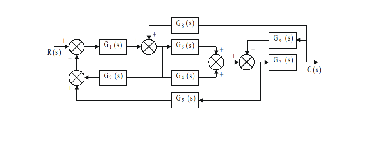

% 3.1 Reduce a system to a single transfer function
imshow(imread("closed_loop.png"))


G1 = tf([0 0 1],[0 1 7]);
G2 = tf([0 0 1],[1 6 5]);
G3 = tf([0 0 1],[0 1 8]);
G4 = tf([0 0 1],[0 1 0]);
G5 = tf([0 0 7],[0 1 3]);
G6 = tf([0 0 1],[1 7 5]);
G7 = tf([0 0 5],[0 1 5]);
G8 = tf([0 0 1],[0 1 9]);
G9 = tf([0 0 1],[0 0 1]);

T1 = append(G1,G2,G3,G4,G5,G6,G7,G8, G9);
Q = [1 -2 -5 9
    2 1 8 0
    3 1 8 0
    4 1 8 0
    5 3 4 -6
    6 7 0 0
    7 3 4 -6
    8 7 0 0];
Inputs = 9;
Outputs = 7;
Ts = connect(T1,Q,Inputs,Outputs);
T = tf(Ts)

T =
 
                    10 s^7 + 290 s^6 + 3350 s^5 + 1.98e04 s^4 + 6.369e04 s^3 + 1.089e05 s^2 + 8.895e04 s + 2.7e04
  ----------------------------------------------------------------------------------------------------------------------------------
  s^10 + 45 s^9 + 866 s^8 + 9305 s^7 + 6.115e04 s^6 + 2.533e05 s^5 + 6.57e05 s^4 + 1.027e06 s^3 + 8.909e05 s^2 + 3.626e05 s + 4.2e04
 
Continuous-time transfer function.


% 3.2 find zeta, wn, Ts, Tp,Tr, pourcent of over shoot and plot the step
% response

clf
numa = 130;
dena = [1 15 130];
Ta = tf(numa,dena)

Ta =
 
        130
  ----------------
  s^2 + 15 s + 130
 
Continuous-time transfer function.
Model Properties


omegana = sqrt(dena(end))

omegana = 11.4018

zetaa = dena(end - 1)/(2*omegana)

zetaa = 0.6578

Tsa = 4/(zetaa*omegana)

Tsa = 0.5333

Tpa = pi/(omegana*sqrt(1-zetaa^2))

Tpa = 0.3658

Tra = (1.76*zetaa^3 - 0.417*zetaa^2 + 1.039*zetaa + 1)/omegana

Tra = 0.1758

percenta = exp(-zetaa * pi/sqrt(1-zetaa^2))*100

percenta = 6.4335


subplot(221)
step(Ta)
title('(a)')

numb = 0.045;
denb = [1 0.025 0.045];
Tb = tf(numb,denb)

Tb =
 
          0.045
  ---------------------
  s^2 + 0.025 s + 0.045
 
Continuous-time transfer function.
Model Properties


omeganb = sqrt(denb(end))

omeganb = 0.2121

zetab = denb(end - 1)/(2*omeganb)

zetab = 0.0589

Tsb = 4/(zetab*omeganb)

Tsb = 320

Tpb = pi/(omeganb*sqrt(1-zetab^2))

Tpb = 14.8354

Trb = (1.76*zetab^3 - 0.417*zetab^2 + 1.039*zetab + 1)/omeganb

Trb = 4.9975

percentb = exp(-zetab * pi/sqrt(1-zetab^2))*100

percentb = 83.0737


subplot(222)
step(Tb)
title('(b)')

numc = 1e9;
denc = [1 1.325e4 1e9];
Tc = tf(numc,denc)

Tc =
 
          1e09
  --------------------
  s^2 + 13250 s + 1e09
 
Continuous-time transfer function.
Model Properties


omeganc = sqrt(denc(end))

omeganc = 3.1623e+04

zetac = denc(end - 1)/(2*omeganc)

zetac = 0.2095

Tsc = 4/(zetac*omeganc)

Tsc = 6.0377e-04

Tpc = pi/(omeganc*sqrt(1-zetac^2))

Tpc = 1.0160e-04

Trc = (1.76*zetac^3 - 0.417*zetac^2 + 1.039*zetac + 1)/omeganc

Trc = 3.8439e-05

percentc = exp(-zetac * pi/sqrt(1-zetac^2))*100

percentc = 51.0123

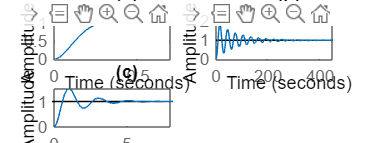


subplot(223)
step(Tc)
title('(c)')

% 3.3 Pole location of a system

den = [1 1 -5 -9 11 -12];
A = roots(den)

A =   -2.1586 + 1.2396i
  -2.1586 - 1.2396i
   2.3339 + 0.0000i
   0.4917 + 0.7669i
   0.4917 - 0.7669i


% 3.4 Pole location for a unit feedback system

numg = 150;
deng = poly([-5 -7 -9 -11]);
G = tf(numg,deng);
pole(G)

ans =   -11.0000
   -9.0000
   -7.0000
   -5.0000



T = feedback(G,1)

T =
 
                   150
  --------------------------------------
  s^4 + 32 s^3 + 374 s^2 + 1888 s + 3615
 
Continuous-time transfer function.
Model Properties


pole(T)

ans =  -10.9673 + 1.9506i
 -10.9673 - 1.9506i
  -5.0327 + 1.9506i
  -5.0327 - 1.9506i


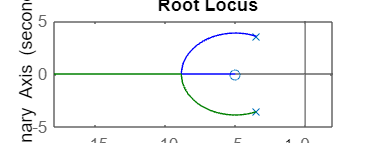

% 3.5 find the root locus plot of a transfer function
clf
num = [1 5];
den = [1 7 25];
rlocus(num, den);

% 3.6 closed loop function
clf
numg = 30*[1 -5 3];
deng = poly([-1 -2 -4 -5]);
G = tf(numg,deng);
T = feedback(G,1)

T =
 
         30 s^2 - 150 s + 90
  ----------------------------------
  s^4 + 12 s^3 + 79 s^2 - 72 s + 130
 
Continuous-time transfer function.
Model Properties


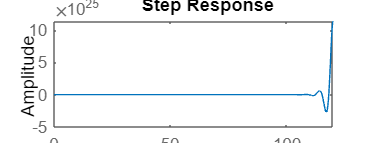

step(T)

% 3.7 the accuracy of a second order approximation

numg = 15*[1 3 7];
deng = conv([1 3 7],poly([-1 -3]));
G = tf(numg,deng)

G =
 
        15 s^2 + 45 s + 105
  --------------------------------
  s^4 + 7 s^3 + 22 s^2 + 37 s + 21
 
Continuous-time transfer function.
Model Properties


T = feedback(G,1)

T =
 
         15 s^2 + 45 s + 105
  ---------------------------------
  s^4 + 7 s^3 + 37 s^2 + 82 s + 126
 
Continuous-time transfer function.
Model Properties


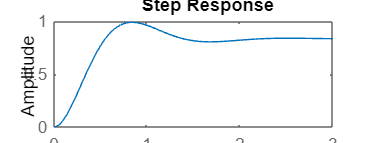

step(T)

% 3.8 Detrmine the stability of G following a range of K

K = 0:0.2:200;

for i = 1:length(K)
    deng = poly([0 -1 -5 -6]);
    dent = deng + [0 0 0 K(i) K(i)];
    R = roots(dent);
    A = real(R);
    B = max(A);
    if B > 0
        R
        K = K(i)
        break
    end
end

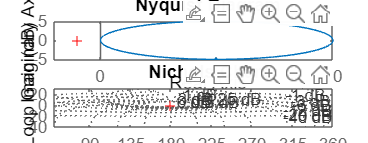

% 3.9 Nyquist and nichols plots
clf
k=30;
z = [-1 -3-7*i -3+7*i];
p = [-1 -3 -3-7*i -3+7*i];
[num, den] = zp2tf(z',p',k);
subplot(211)
nyquist(num,den)
subplot(212)
nichols(num,den)
ngrid
axis([50 360 -40 30])

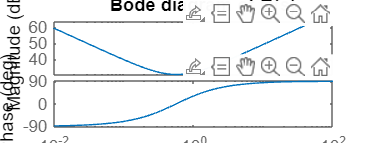

% 3.10 Bode diagram of a controller
clf
num = [29.125 33.2025 9.4627];
den = [0 1 0];
bode(num,den)
title('Bode diagram of G(s)')

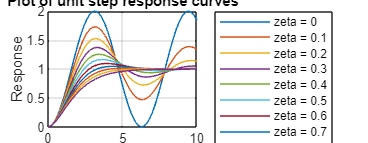

% 3.11 unit step response of different curves

t = 0:0.2:10;
zeta = 0:0.1:1;

for n = 1:length(zeta)
    num = [0 0 1];
    den = [1 2*zeta(n) 1];
    [y(1:51,n),x,t] = step(num,den,t);

end

plot(t,y)
grid
title('Plot of unit step response curves')
xlabel('t [sec]')
ylabel('Response')
legend('zeta = 0','zeta = 0.1','zeta = 0.2','zeta = 0.3','zeta = 0.4','zeta = 0.5','zeta = 0.6','zeta = 0.7','zeta = 0.8','zeta = 0.9','zeta = 1')

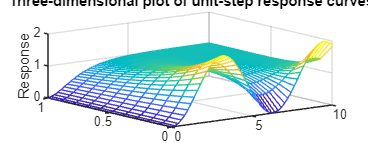


% three dimensional plot of (t,zeta,y) using mesh
mesh(t,zeta,y')
title ('Three-dimensional plot of unit-step response curves')
xlabel('t (sec)')
ylabel('\zeta')
zlabel('Response')

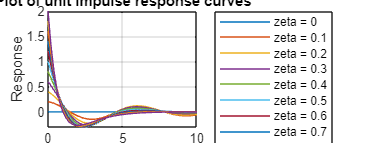

% 3.12 unit step response of different curves

t = 0:0.2:10;
zeta = 0:0.1:1;

for n = 1:length(zeta)
    num = [0 2*zeta(n) 0];
    den = [1 2*zeta(n) 1];
    [y(1:51,n),x,t] = impulse(num,den,t);

end

plot(t,y)
grid
title('Plot of unit impulse response curves')
xlabel('t [sec]')
ylabel('Response')
legend('zeta = 0','zeta = 0.1','zeta = 0.2','zeta = 0.3','zeta = 0.4','zeta = 0.5','zeta = 0.6','zeta = 0.7','zeta = 0.8','zeta = 0.9','zeta = 1')

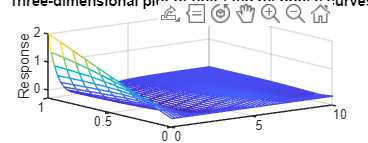


% three dimensional plot of (t,zeta,y) using mesh
mesh(t,zeta,y')
title ('Three-dimensional plot of unit-step response curves')
xlabel('t (sec)')
ylabel('\zeta')
zlabel('Response')

% 3.13 Obtain a bode plote, overshoot, settling time and peak time

% G(s) = 50*(s+1)/(s*(s+3)*(s+5))
G = zpk(-1,[0 -3 -5],50)

G =
 
    50 (s+1)
  -------------
  s (s+3) (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


G = tf(G)

G =
 
      50 s + 50
  ------------------
  s^3 + 8 s^2 + 15 s
 
Continuous-time transfer function.
Model Properties


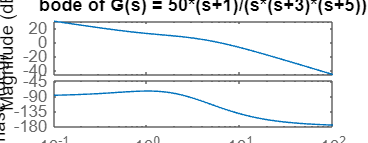

bode(G)
title('bode of G(s) = 50*(s+1)/(s*(s+3)*(s+5))')

[Gm, Pm, Wcg, Wcp] = margin(G); %find magnitude margine and phase margine
w = 1:0.01:20;
[M,P,w] = bode(G,w);

for k = 1:length(M) % find the bandwidth
    if 20*log10(M(k)) + 7 <= 0
        'Mag'
        20*log10(M(k))
        'BW'
        wBW = w(k)
        break
    end
end

ans = 'Mag'

ans = -7.0032

ans = 'BW'

wBW = 9.7900


for z = 0:0.01:10
    Pt = atan(2*z/(sqrt(-2*z^2 + sqrt(1 + 4*z^4))))*(180/pi);
    
    if (Pm - Pt)<=0
        z; % damping ratio
        Po = exp(-z*pi/sqrt(1-z^2)); % percent overshoot
        Ts = (4/ (wBW*z))*sqrt ((1 - 2*z^2) + sqrt (4*z^4 - 4*z^2 + 2)); %settling time
        Tp = (pi/ (wBW*sqrt (1 - z^2)))*sqrt ((1 - 2*z^2) + sqrt (4*z^4 - 4*z^2 + 2)); % peak time
        fprintf ('Bandwidth = %g', wBW)
        fprintf ('Phase margin = %g', Pm)
        fprintf ('Damping ratio = %g', z)
        fprintf ('Percent overshoot = %g', Po*100)
        fprintf ('settling time = %g', Ts)
        fprintf ('Peak time = %g', Tp)
        break
    end
end

Bandwidth = 9.79

Phase margin = 57.892

Damping ratio = 0.59

Percent overshoot = 10.0693

settling time = 0.804303

Peak time = 0.461606

T = feedback(G,1)

T =
 
         50 s + 50
  -----------------------
  s^3 + 8 s^2 + 65 s + 50
 
Continuous-time transfer function.
Model Properties


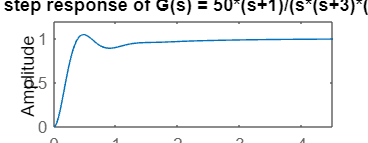

step(T)
title('step response of G(s) = 50*(s+1)/(s*(s+3)*(s+5))')


% G(s) = 25*(s+1)*(s+7)/(s*(s+2)*(s+4)*(s+8))
G = zpk([-1 -7],[0 -2 -4 -8],25)

G =
 
    25 (s+1) (s+7)
  -------------------
  s (s+2) (s+4) (s+8)
 
Continuous-time zero/pole/gain model.
Model Properties


G = tf(G)

G =
 
      25 s^2 + 200 s + 175
  ----------------------------
  s^4 + 14 s^3 + 56 s^2 + 64 s
 
Continuous-time transfer function.
Model Properties


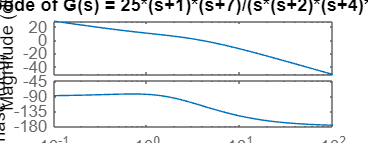

bode(G)
title('bode of G(s) = 25*(s+1)*(s+7)/(s*(s+2)*(s+4)*(s+8)')

[Gm, Pm, Wcg, Wcp] = margin(G); %find magnitude margine and phase margine
w = 1:0.01:20;
[M,P,w] = bode(G,w);

for k = 1:length(M) % find the bandwidth
    if 20*log10(M(k)) + 7 <= 0
        'Mag'
        20*log10(M(k))
        'BW'
        wBW = w(k)
        break
    end
end

ans = 'Mag'

ans = -7.0110

ans = 'BW'

wBW = 6.5500


for z = 0:0.01:10
    Pt = atan(2*z/(sqrt(-2*z^2 + sqrt(1 + 4*z^4))))*(180/pi);
    
    if (Pm - Pt)<=0
        z; % damping ratio
        Po = exp(-z*pi/sqrt(1-z^2)); % percent overshoot
        Ts = (4/ (wBW*z))*sqrt ((1 - 2*z^2) + sqrt (4*z^4 - 4*z^2 + 2)); %settling time
        Tp = (pi/ (wBW*sqrt (1 - z^2)))*sqrt ((1 - 2*z^2) + sqrt (4*z^4 - 4*z^2 + 2)); % peak time
        fprintf ('Bandwidth = %g', wBW)
        fprintf ('Phase margin = %g', Pm)
        fprintf ('Damping ratio = %g', z)
        fprintf ('Percent overshoot = %g', Po*100)
        fprintf ('settling time = %g', Ts)
        fprintf ('Peak time = %g', Tp)
        break
    end
end

Bandwidth = 6.55

Phase margin = 63.1105

Damping ratio = 0.67

Percent overshoot = 5.86969

settling time = 0.959175

Peak time = 0.679904

T = feedback(G,1)

T =
 
         25 s^2 + 200 s + 175
  -----------------------------------
  s^4 + 14 s^3 + 81 s^2 + 264 s + 175
 
Continuous-time transfer function.
Model Properties


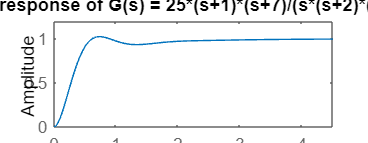

step(T)
title('step response of G(s) = 25*(s+1)*(s+7)/(s*(s+2)*(s+4)*(s+8)')

% 3.14 feedback system with a forward path transfer function
% G(s) = K/(s*(s+5)*(s+12)) and delay of 0.5 second and
% Gain K = 40

% estimate the percent overshoot for K = 40 using a second order
% approximation

numg1 = 1;
deng1 = poly([0 -5 -12]);
'G1(s)'

ans = 'G1(s)'

G1 = tf(numg1,deng1)

G1 =
 
           1
  -------------------
  s^3 + 17 s^2 + 60 s
 
Continuous-time transfer function.
Model Properties



[numg2,deng2] = pade(0.5,5);
'G2(s)'

ans = 'G2(s)'

G2 = tf(numg2,deng2)

G2 =
 
  -s^5 + 60 s^4 - 1680 s^3 + 2.688e04 s^2 - 2.419e05 s + 9.677e05
  ---------------------------------------------------------------
  s^5 + 60 s^4 + 1680 s^3 + 2.688e04 s^2 + 2.419e05 s + 9.677e05
 
Continuous-time transfer function.
Model Properties



'G(s) = G1(s)G2(s)'

ans = 'G(s) = G1(s)G2(s)'

G = G1*G2

G =
 
                  -s^5 + 60 s^4 - 1680 s^3 + 2.688e04 s^2 - 2.419e05 s + 9.677e05
  ------------------------------------------------------------------------------------------------
  s^8 + 77 s^7 + 2760 s^6 + 5.904e04 s^5 + 7.997e05 s^4 + 6.693e06 s^3 + 3.097e07 s^2 + 5.806e07 s
 
Continuous-time transfer function.
Model


K = input('Type a gain K');

T = feedback(K*G,1)

T =
 
                   -40 s^5 + 2400 s^4 - 6.72e04 s^3 + 1.075e06 s^2 - 9.677e06 s + 3.871e07
  ---------------------------------------------------------------------------------------------------------
  s^8 + 77 s^7 + 2760 s^6 + 5.9e04 s^5 + 8.021e05 s^4 + 6.626e06 s^3 + 3.204e07 s^2 + 4.838e07 s + 3.871e07
 
Continuous-time transfer function.


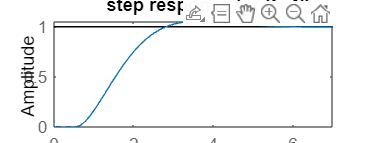

step(T)

title(['step response for K=', num2str(K)])

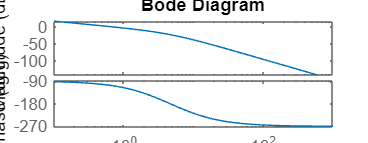

% 3.15 bode plot of two transfer function

% G(s) = 15 / (s*(s+3)*(0.7*s+5))
clf
num = 15;
den = poly([0 -3 -5/0.7]);
bode(num,den)

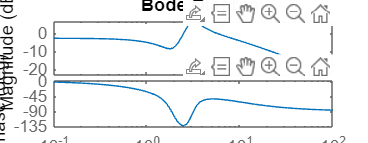


% G(s) = 15 / (s*(s+3)*(0.7*s+5))
num = [0 7 15 7 80];
den = [1 8 12 70 110];
bode(num,den)

% 3.16 Plot nyquist diagram of G(s) = K*(s+7)/((s^2 + 3*s + 52)*(s^2 + 2*s + 35))

numg = [1 7];
deng = conv([1,3,52],[1,2,35])

deng =            1           5          93         209        1820


'G(s)'

ans = 'G(s)'

G = tf(numg,deng)

G =
 
                 s + 7
  -----------------------------------
  s^4 + 5 s^3 + 93 s^2 + 209 s + 1820
 
Continuous-time transfer function.
Model Properties


Gap = zpk(G)

Gap =
 
               (s+7)
  -------------------------------
  (s^2 + 2s + 35) (s^2 + 3s + 52)
 
Continuous-time zero/pole/gain model.
Model Properties


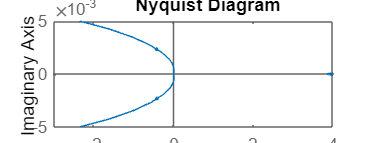

nyquist(G)
axis([-3e-3 4e-3 -5e-3 5e-3])

w = 0:0.1:100;
[re,im] = nyquist(G,w);

for i = 1:length(w)

    M(i) = abs(re(i) + j*im(i));
    A(i) = atan2(im(i),re(i))*(180/pi);
    if 180 - abs(A(i)) <= 1
        re(i);
        im(i);
        K = 1/abs(re(i));
        fprintf('\nw = %g',w(i))
        fprintf('Re = %g',re(i))
        fprintf('Im = %g',im(i))
        fprintf('M = %g',M(i))
        fprintf('K= %g',K)
        Gm = 20*log10(1/M(i));
        fprintf('Gm = %g',Gm)
        break
    end

end

% 3.17 Bode of system G(s) = K/(s*(s+3)*(s+12))
numg = 1;
deng = poly([0 -3 -12]);
'G(s)'

ans = 'G(s)'

G = tf(numg,deng)

G =
 
           1
  -------------------
  s^3 + 15 s^2 + 36 s
 
Continuous-time transfer function.
Model Properties


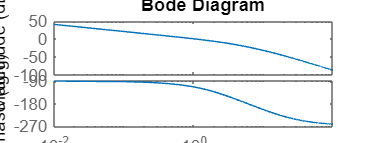

w = 0.01:0.1:100;
K = input('Type gain K ');
bode(K*G, w)


[M,P] = bode(K*G, w);

% Compute gain margin
for i = 1:length(P)
    if P(i) <= -180
        fprintf('\nGain K = %g',K)
        fprintf('\nFrequency at (180 degree) = %g',w(i))
        fprintf('\nMagnitude = %g',M(i))
        fprintf('\nMagnitude (dB) = %g',20*log10(M(i)))
        fprintf('\nPhase = %g',P(i))
        Gm = 20*log10(1/M(i));
        fprintf('\nGain margin (dB) = %g',Gm)
        break
    end
end


Gain K = 40


Frequency at (180 degree) = 6.01


Magnitude = 0.0738277


Magnitude (dB) = -22.6356


Phase = -180.076


Gain margin (dB) = 22.6356

 
% compute phase margin

for i = 1:length(M)
    if M(i) <= 1
        fprintf('\nGain K = %g',K)
        fprintf('\nFrequency at (0dB) = %g',w(i))
        fprintf('\nMagnitude = %g',M(i))
        fprintf('\nMagnitude (dB) = %g',20*log10(M(i)))
        fprintf('\nPhase = %g',P(i))
        Pm = 180 + P(i);
        fprintf('\nPhase margin (degree) = %g',Pm)
        break
    end
end


Gain K = 40


Frequency at (0dB) = 1.11


Magnitude = 0.93481


Magnitude (dB) = -0.585534


Phase = -115.589


Phase margin (degree) = 64.4107


% Alternative way to compute margins of a transfer function
clf
numg = 1;
deng = poly([0 -3 -12]);
'G(s)'

ans = 'G(s)'

G = tf(numg,deng)

G =
 
           1
  -------------------
  s^3 + 15 s^2 + 36 s
 
Continuous-time transfer function.
Model Properties


w = 0.01:0.1:100;
K = input('Type gain K ');
bode(K*G, w)

[Gm,Pm,Wcp,Wcg] = margin(K*G)

Gm = 13.5000

Pm = 65.8119

Wcp = 6

Wcg = 1.0453

'Gm(dB)'

ans = 'Gm(dB)'

20*log10(Gm)

ans = 22.6067

'Pm (degree)'

ans = 'Pm (degree)'

Pm

Pm = 65.8119

% 3.18 study of system G(s) = K*(s+5)/(s*(s^2 +3*s + 15))
numg = [1 5];
deng = [1 3 15 0];
'G(s)'

ans = 'G(s)'

G = tf(numg,deng)

G =
 
        s + 5
  ------------------
  s^3 + 3 s^2 + 15 s
 
Continuous-time transfer function.
Model Properties


K = input('Type gain K ');

% Display the closed loop magnitude and phase frequency response for unity
% feedback system
'T(s)'

ans = 'T(s)'

T = feedback(K*G,1)

T =
 
         40 s + 200
  ------------------------
  s^3 + 3 s^2 + 55 s + 200
 
Continuous-time transfer function.
Model Properties


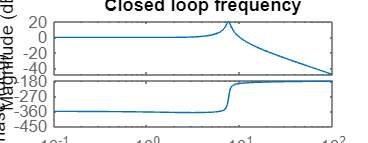

bode(T)
title('Closed loop frequency')

[M,P,w] = bode(T);

% Peak of magnitude, frequency of peak magnitude and bandwidth of closed
% loop frequency
[Mp ind] = max(M);
Mp

Mp = 11.1162

MpdB = 20*log10(Mp)

MpdB = 20.9192

wp = w(ind)

wp = 7.5295


for i = 1:length(M)
    if M(i) <= 0.707
        fprintf('Bandwidth = %g', w(i))
        break
    end
end

Bandwidth = 11.2549

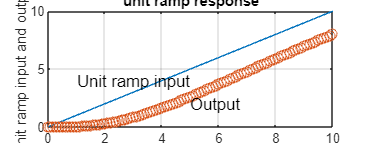

% 3.19 unit ramp response of G(s) = 1/(3*s^2 + 2*s + 1)

num = [0 0 1];
den = [3 2 1];
t = 0:0.1:10;
r = t;
y = lsim(num,den,r,t); % simulate a ramp
plot(t,r,'-',t,y,'o')
grid
title('unit ramp response')
xlabel('t sec')
ylabel('Unit ramp input and output')
text(1,4,'Unit ramp input')
text(5,2,'Output')

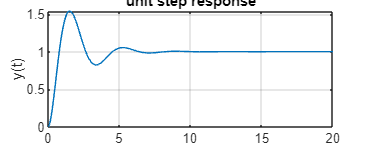

% 3.20 unit step response of G(s) = (7*s^2 + 16*s + 10)/(s^4 + 5*s^3 + 11*s^2 + 16*s + 10)

num = [0 0 7 16 10];
den = [1 5 11 16 10];
t = 0:0.02:20;
[y,x,t] = step(num,den,t); % simulate a step
plot(t,y)
grid
title('unit step response')
xlabel('t sec')
ylabel('y(t)')


% rise time (from 10% to 90%)
r1 = 1;
while y(r1) < 0.1
    r1 = r1 + 1;
end

r2 = 1;
while y(r2) < 0.9
    r2 = r2 + 1;
end

rise_time = (r2 - r1)*0.02

rise_time = 0.5400


% peak time
[ymax,tp] = max(y);
peak_time = (tp - 1)*0.02

peak_time = 1.5200


% overshoot in %
max_overshoot = ymax - 1

max_overshoot = 0.5397


% settling time
s = 1001;
while y(s)>0.98 & y(s)<1.02
    s = s-1;
end
settling_time = (s-1)*0.02

settling_time = 6.0200

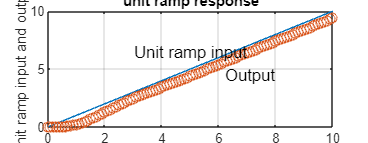

% 3.21 unit ramp response of the following closed loop system G(s) = (s +
% 12)/(s^3 + 5s^2 + 8*s + 12)

num = [0 0 1 12];
den = [1 5 8 12];
t = 0:0.1:10;
r = t;
y = lsim(num,den,r,t); % simulate a ramp
plot(t,r,'-',t,y,'o')
grid
title('unit ramp response')
xlabel('t sec')
ylabel('Unit ramp input and output')
text(3,6.5,'Unit ramp input')
text(6.2,4.5,'Output')

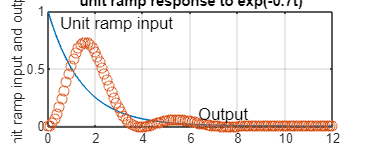


% input = r1 = exp(-0.7*t)
t = 0:0.1:12;
r1 = exp(-0.7*t);
y = lsim(num,den,r1,t); % simulate a ramp
plot(t,r1,'-',t,y,'o')
grid
title('unit ramp response to exp(-0.7t)')
xlabel('t sec')
ylabel('Unit ramp input and output')
text(0.5,0.9,'Unit ramp input')
text(6.3,0.1,'Output')

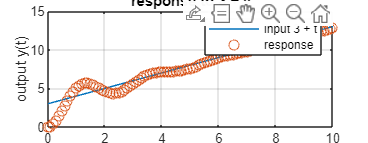

% 3.22 unit ramp response of  G(s) = 7/(s^2 + s + 7)

num = [0 0 7];
den = [1 1 7];
t = 0:0.1:10;
r = 3 + t;
y = lsim(num,den,r,t); % simulate a ramp
plot(t,r,'-',t,y,'o')
grid
title('response to 3 + y')
xlabel('t sec')
ylabel('output y(t)')
legend('input 3 + t','response')

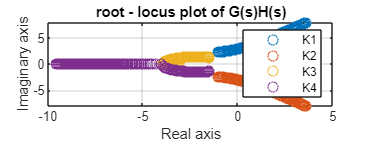

% 3.23 find the root locus plot of open loop transfer function
% G(s)H(s) = K*(s + 3)/((s^2 + 3*s + 4)(s^2 + 2s + 7))
clf
num = [0 0 0 1 3];
den = conv([1 3 4],[1 2 7]);
K1 = 0:0.1:2;
K2 = 2:0.02:2.5;
K3 = 2.5:0.5:10;
K4 = 10:50;
K5 = 50:5:800;
K = [K1 K2 K3 K4 K5];
r = rlocus(num, den, K);
plot(r,'o')
axis([-10 5 -8 8]);
grid
title('root - locus plot of G(s)H(s)')
xlabel('Real axis')
ylabel('Imaginary axis')
legend('K1','K2', 'K3', 'K4')

% 3.24 unity feedback control system with feedforward transfer function
% G(s) = K/(s(s^2 + 5s + 9)) with K = 3

% Poles of closed loop transfer function
p = [1 5 9 3];
roots(p)

ans =   -2.2874 + 1.3500i
  -2.2874 - 1.3500i
  -0.4253 + 0.0000i


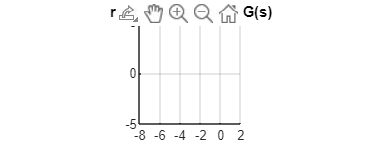


% root locus of G(s)
clf
num = 1;
den = [1 5 9 0];
r = rlocus(num, den);
axis([-8 2 -5 5],'square')
grid
title('root - locus plot of G(s)')

% 3.25 Plot nyquist diagram of G(s) = 1/(s^3 + 0.3*s^2 + 5s + 1)

% poles of G
p = [1 0.3 5 1];
roots(p)

ans =   -0.0496 + 2.2311i
  -0.0496 - 2.2311i
  -0.2008 + 0.0000i



% nyquist of G
num = [0 0 0 1];
den = [1 0.3 5 1];
nyquist(num, den)
axis([-3 3 -2 2]);
axis('square');

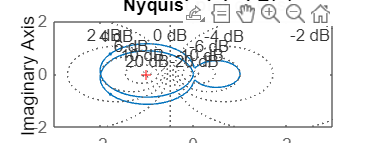

grid
title('Nyquist plot of G(s)')

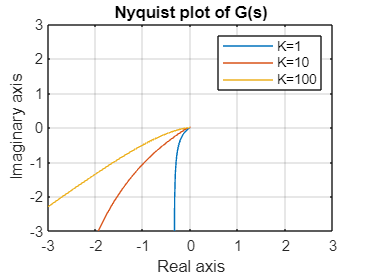

% 3.26 Plot nyquist diagram of G(s) = K*(s+3)/(s^3 + 8s^2 + 7s) for K = 1
% K = 10 and K = 100;

% nyquist of G
num = [1 3];
den = [1 8 7 0];
w = 0.1:0.1:100;
[re1,im1,w] = nyquist(num, den,w);
[re2,im2,w] = nyquist(10*num, den,w);
[re3,im3,w] = nyquist(100*num, den,w);
plot(re1,im1,re2,im2,re3,im3)
axis([-3 3 -3 3]);
grid
title('Nyquist plot of G(s)')
xlabel('Real axis')
ylabel('Imaginary axis')
legend('K=1','K=10','K=100')

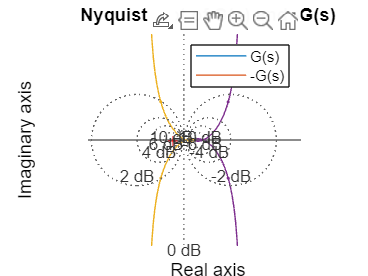

% 3.27 Plot nyquist diagram of G(s) = 5/(s^3 + 4s^2 + 3s) and -G(s)

num1 = 5;
den1 = [1 4 3 0];
num2 = -5;
den2 = [1 4 3 0];
nyquist(num1,den1)
hold on
nyquist(num2,den2)
axis([-5 5 -5 5]);
grid on
title('Nyquist plot of G(s) and -G(s)')
xlabel('Real axis')
ylabel('Imaginary axis')
legend('G(s)','-G(s)')
hold off

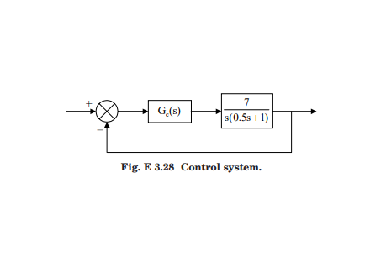

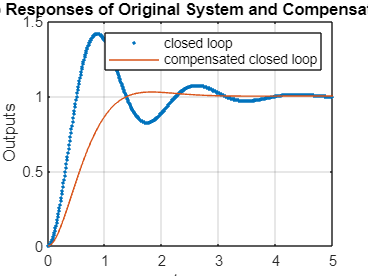

% 3.28 Design compensator such dominant closed loop poles at s = -2 +ou-

% sqrt(3)j and plot unit step response

imshow(imread("closed_loop_2.png"));

% Gc(s) = 0.5*(s+2)/(s+4)
% Closed loop G(s) = 14/(s^2 + 2s + 14)
num = 14;
den = [1,2,14];

% Compensated closed loop G(s) = 7/(s^2 + 4s + 7)
numc = 7;
denc = [1,4,7];

t = 0:0.01:5;
c1 = step(num,den,t);
c2 = step(numc,denc,t);
plot(t,c1,'.',t,c2,'-')
xlabel('t sec')
ylabel('Outputs')
legend('closed loop','compensated closed loop')
grid on
title('Unit-Step Responses of Original System and Compensated System')

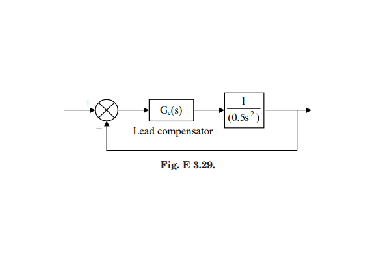

% 3.29 Design compensator such dominant closed loop poles at s = -1 +ou- j
% and plot unit step and unit ramp responses

imshow(imread("closed_loop3.png"));

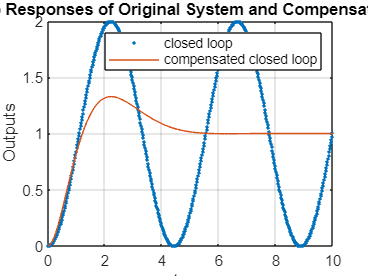


% Gc(s) = 2*(s+0.5)/(s+3)
% Closed loop G(s) = 2/(s^2 + 2)
num = 2;
den = [1 0 2];

% Compensated closed loop G(s) = (4s + 2)/(s^3 + 3s^2 + 4s + 2)
numc = [4 2];
denc = [1 3 4 2];

% unit step response
t = 0:0.02:10;
c1 = step(num,den,t);
c2 = step(numc,denc,t);
plot(t,c1,'.',t,c2,'-')
xlabel('t sec')
ylabel('Outputs')
legend('closed loop','compensated closed loop')
grid on
title('Unit-Step Responses of Original System and Compensated System')

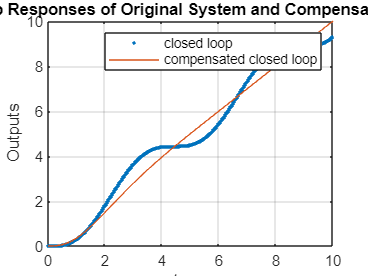


% unit ramp response
t = 0:0.02:10;
r = t;
c1 = lsim(num,den,r,t); % simulate a ramp
c2 = lsim(numc,denc,r,t);
plot(t,c1,'.',t,c2,'-')
xlabel('t sec')
ylabel('Outputs')
legend('closed loop','compensated closed loop')
grid on
title('Unit-ramp Responses of Original System and Compensated System')

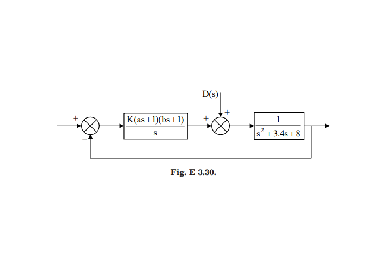

% 3.30 Design PID controller such that the response to any step disturbance
% will be damped out in 2 to 3 secs in term of settling time

imshow(imread("closed_loop_4.png"));

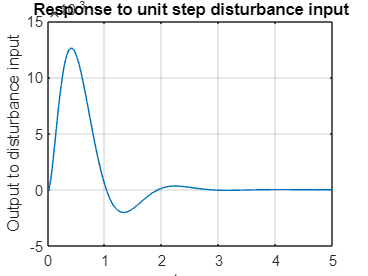


% response to unit distirbance input
% for designing PID controller we choose for closed loop transfer function
% a second order with zeta = 0.5 and wn = 4 rad/s and a third pole s = -10
% It will give Gc(s) = 10.6*(s^2+4.528s+15.09)/s

% Closed loop Gd(s) = s/(s^3 + 14s^2 + 56s + 160) for disturbance input
numd = [1 0];
dend = [1 14 56 160];
t = 0:0.01:5;
[c1,x1,t] = step(numd,dend,t);
plot(t,c1)
grid on
title('Response to unit step disturbance input')
xlabel('t sec')
ylabel('Output to disturbance input')

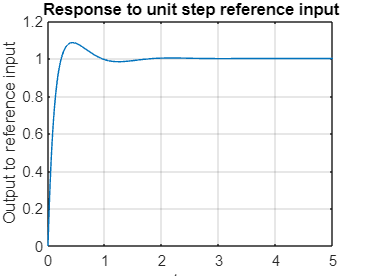


% Closed loop Gr(s) = (10.6s^2 + 48s + 160)/(s^3 + 14s^2 + 56s + 160) for reference input
numr = [10.6 48 160];
denr = [1 14 56 160];
t = 0:0.01:5;
[c2,x2,t] = step(numr,denr,t);
plot(t,c2)
grid on
title('Response to unit step reference input')
xlabel('t sec')
ylabel('Output to reference input')

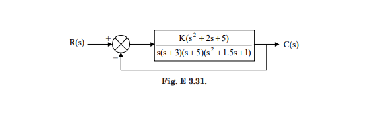

% 3.31 find possible range K for stability and plot of root locus

imshow(imread("closed_loop_5.png"));

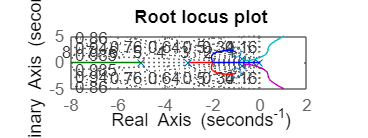


% Open loop transfer function G(s) = K*(s^2 + 2s + 5)/(s(s+3)*(s+5)*(s^2 +
% 1.5s + 1)

num = [1 2 5];
den = [1 9.5 28 30.5 15 0];
rlocus(num,den)
axis([-8 2 -5 5]);
grid on
title('Root locus plot')


% we notice that the system is conditionally stable. All critical points
% for stability lie on the jω axis

% To obtain the crossing points of the root loci with the jω axis, we substitute s = jω into the
% characteristic equation of closed loop transfer function 
% s^5 + 9.5s^4 + 28s^3 + 20s^2 + 15s + K(s^2 + 2s + 5) = 0
% (9.5w^4 - (30.5+K)*w^2 + 5K) + j*(w^5 - 28w^3 +(15+2K)*w) = 0
% (9.5w^4 - (30.5+K)*w^2 + 5K) = 0 & (w^5 - 28w^3 +(15+2K)*w) = 0
% find K by second equation above K = (-w^4 - 28*w^2 - 15)/2
% 0.5*w^6 - 7*w^4 + 47*w^2 - 37.5 = 0

a = [0.5 0 -7 0 47 0 -37.5];
roots(a)

ans =   -2.7929 + 1.1213i
  -2.7929 - 1.1213i
   2.7929 + 1.1213i
   2.7929 - 1.1213i
  -0.9562 + 0.0000i
   0.9562 + 0.0000i



% The gain value at 0.9562
K = (- 0.9562^4 + 28*0.9562^2 - 15)/2

K = 4.8825


% Range of gain K for stability 4.8825 > K > 0

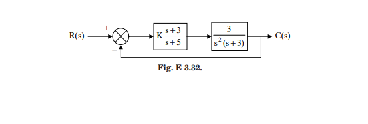

% 3.32 find possible range K for stability and plot of root locus

imshow(imread("closed_loop_6.png"));

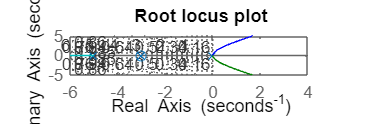


% Open loop transfer function G(s) = 3K*(s + 3)/(s^2*(s+3)*(s+5))

num = [3 9];
den = [1 8 15 0 0];
rlocus(num,den)
axis([-6 4 -5 5]);
grid on
title('Root locus plot')


% we notice that the system is conditionally stable. All critical points
% for stability lie on the jω axis

% To obtain the crossing points of the root loci with the jω axis, we substitute s = jω into the
% characteristic equation of closed loop transfer function 
% s^4 + 8s^3 + 15s^2 + 3Ks + 9K = 0
% (w^4 - 15w^2 + 9K) + jw(-8w^2 + 3K) = 0
% (w^4 - 15w^2 + 9K) = 0 & w(-8w^2 + 3K) = 0
% find K by second equation above K = 8w^2 / 3
% w^4 + 9w^2 = 0


% The gain value at w = 3
K = 8*(3)^2 / 3

K = 24


% Range of gain K for stability 24 > K > 0

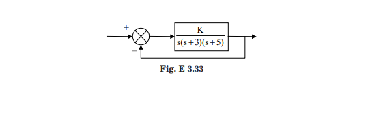

% 3.33 study of control system where open loop transfer function G(s) = K/(s*(s+3)*(s+5))

imshow(imread("closed_loop_7.png"));

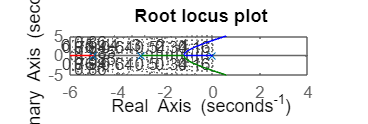


% The root locus plot

num = 1;
den = [1 8 15 0];
rlocus(num,den)
axis([-6 4 -5 5]);
grid on
title('Root locus plot')

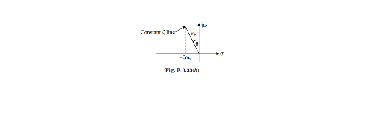


% find the gain K where zeta = 0.6 of the dominant closed loop poles 

imshow(imread("closed_loop_8.png"));

% sin(theta) = zeta*wn/wn = zeta

% Also that ζ = 0.6 line can be defined by s = -0.75*a + j*a where a>0
% s(s+3)(s+5) + K = 0

syms a K
eq = (-0.75*a + j*a)*(-0.75*a + j*a + 3)*(-0.75*a + j*a + 5) + K

$$eq = K+a\,\left(-3+a\,\left(\frac{3}{4}-\mathrm{i}\right)\right)\,\left(-5+a\,\left(\frac{3}{4}-\mathrm{i}\right)\right)\,\left(-\frac{3}{4}+\mathrm{i}\right)$$

eq = expand(eq)

$$eq = a^{3}\,\left(\frac{117}{64}+\frac{11}{16}\,\mathrm{i}\right)+a^{2}\,\left(-\frac{7}{2}-12\,\mathrm{i}\right)+a\,\left(-\frac{45}{4}+15\,\mathrm{i}\right)+K$$


% The characteristic equation is
% (1.8281*a^3 - 3.5*a^2 - 11.25*a + K) + j*(0.6875*a^3 - 12*a^2 + 15*a) = 0
% (1.8281*a^3 - 3.5*a^2 - 11.25*a + K) = 0 & (0.6875*a^3 - 12*a^2 + 15*a) = 0

eq1 = ((0.6875*a^3 - 12*a^2 + 15*a)==0)

$$eq1 = \frac{11\,a^{3}}{16}-12\,a^{2}+15\,a=0$$

solve(eq1,a)

$$ans = \left(\begin{array}{c} 0\\ \frac{96}{11}-\frac{4\,\sqrt{411}}{11}\\ \frac{4\,\sqrt{411}}{11}+\frac{96}{11} \end{array}\right)$$


% the solutions are a = 0, a = 1.3552, a = 707.7167
% K = -1.8281*a^3 + 3.5*a^2 + 11.25*a

K = @(a) -1.8281*a^3 + 3.5*a^2 + 11.25*a

K = function_handle with value:
    @(a)-1.8281*a^3+3.5*a^2+11.25*a



% For a = 1.3552
K(1.3552)

ans = 17.1240

% For a = 707.7167
K(707.7167)

ans = -6.4624e+08


% we take the positive value of K = 17.1240
% The characteristic equation is s^3 + 8*s + 15*s + 17.1240

p = [1 8 15 17.1240];
roots(p)

ans =   -5.9672 + 0.0000i
  -1.0164 + 1.3552i
  -1.0164 - 1.3552i


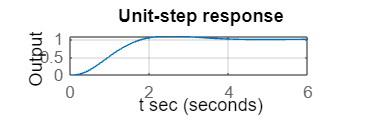


% unit response of the system with K = 17.1240
num = [17.1240];
den = [1 8 15 17.1240];
step(num,den)
grid on
title('Unit-step response')
xlabel('t sec')
ylabel('Output')

% 3.34 Design a compensator for a system where open loop transfer function G(s) = 1/(s*(s+2)*(0.6s+1))

imshow(imread("closed_loop_9.png"));

% The compensator form

imshow(imread("closed_loop_10.png"));

% condition on velocity error (Kv) = 5, the phase margin = 50 degree
% gain margine = 10 dB

% we have Kc*beta = K & G1 = K*G & Kv = lim s*Gc(s)*G(s) = lim s*G1(s)
% Kv = K/2 = 5
% so K = 10

% bode of G1(jw) = 10/(s(s+2)(0.6s+1))

num = 10;
den = [0.6 2.2 2 0];
bode(num,den)
grid on
title('Bode diagram')
G1 = tf(num,den)
[Gm, Pm, Wcg, Wcp] = margin(G1)
% G1 is unstable même si is in closed loop

% add lag compensator
% We have 20log(1/beta) = -20
beta = 10;

% other corner frequency is (1/(beta*T)) = 0.01 rad/s
% we have so Gc(s) = Kc(10)*(10s + 1)/(100s + 1)
% Kc = K/beta
Kc = 1;

% so Gc(s) = (10s + 1)/(100s + 1)

% The open loop transfer function is Gc(s)*G(s)
% bode diagram for Gc(s)*G(s) = 10*(10s+1)/(s*(100s+1)*(s+2)*(0.4s+1))

num = [100 10];
den = [60 220.6 202.2 2 0];
bode(num,den)
grid on
title('Bode diagram')
G = tf(num,den)
[Gm, Pm, Wcg, Wcp] = margin(G)

% Gc(s) = 10*(10s+1)/(0.6s+1)
% non compensated Closed loop G(s) = 1/(0.6s^3+ 2.2s^2 + 2s + 1)
num = 1;
den = [0.6 2.2 2 1];

% Compensated closed loop G(s) = (100s + 10)/(60s^4 + 220.6*s^3 + 202.2s^2 + 102s + 10)
numc = [100 10];
denc = [60 220.6 202.2 102 10];

% unit-step response
clf
t = 0:0.1:40;
[c1,x1,t] = step(num,den,t);
[c2,x2,t] = step(numc,denc,t);
plot(t,c1,'.',t,c2,'-')
xlabel('t sec')
ylabel('Outputs')
legend('uncompensated closed loop','compensated closed loop')
grid on
title('Unit-Step Responses of Original System and Compensated System')

% unit-ramp response
clf
t = 0:0.1:20;
r = t;
c1 = lsim(num,den,r,t); % simulate a ramp
c2 = lsim(numc,denc,r,t);
plot(t,r,'-',t,c1,'o',t,c2,'--')
grid on
title('unit ramp response')
xlabel('t sec')
ylabel('Outputs')
legend('ramp','uncompensated closed loop','compensated closed loop')
title('Unit-ramp Responses of Original System and Compensated System')

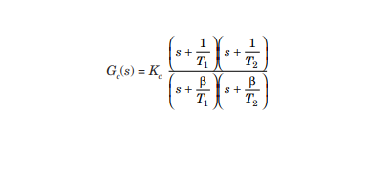

% 3.35 Design a compensator for a system where open loop transfer function G(s) = K/(s*(s+3)*(s+5))


% The compensator form

imshow(imread("closed_loop_11.png"));

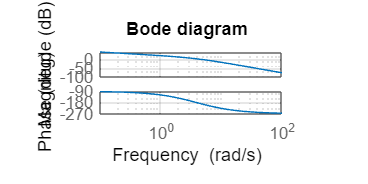


% condition on velocity error (Kv) = 10 s^-1, the phase margin = 50 degree
% gain margine > 10 dB

% we have Kc*beta = K & G1 = K*G & Kv = lim s*Gc(s)*G(s) = lim s*G1(s)*K
% Kv = K/15 = 10
% so K = 150

% bode of G(s) = 150/(s*(s+3)*(s+5))


num = 150;
den = [1 8 15 0];
bode(num,den)
grid on
title('Bode diagram')

G = tf(num,den)

G =
 
         150
  ------------------
  s^3 + 8 s^2 + 15 s
 
Continuous-time transfer function.
Model Properties


[Gm, Pm, Wcg, Wcp] = margin(G)

Gm = 0.8000

Pm = -6.0246

Wcg = 3.8730

Wcp = 4.3181

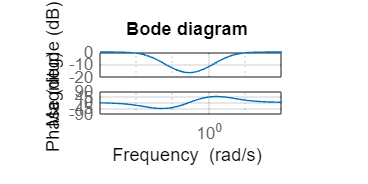

% G is unstable même si is in closed loop

% add lag-lead compensator
% new gain crossover frequency w = 2 rad/s
% corner frequency w = 1/T2
% anoter corner frequency w = 1/(beta*T2)
% We have sin(phase margin) = (beta - 1)/(beta + 1)

beta = 10;

% other corner frequency is w = 0.4 rad/s and w = 4 rad/s
% we have so Gc(s) = ((s + 0.4)/(s + 4))*((s + 0.2)/(s + 0.02)) for Kc = 1

Kc = 1;

% The open loop transfer function is Gc(s)*G(s)
% bode diagram of designed compensator
num = [1 0.6 0.08];
den = [1 4.02 0.08];
bode(num,den)
grid on
title('Bode diagram')

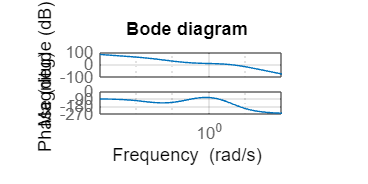


% bode diagram for Gc(s)*G(s) = ((s + 0.4)/(s + 4))*((s + 0.2)/(s + 0.02))
% *(150/(s*(s+3)*(s+5)))

a = [1 4.02 0.08];
b = [1 8 15 0];

num = [150 0.6*150 0.08*150];
den = conv(a,b);
bode(num,den)
grid on
title('Bode diagram')

G = tf(num,den)

G =
 
                150 s^2 + 90 s + 12
  -----------------------------------------------
  s^5 + 12.02 s^4 + 47.24 s^3 + 60.94 s^2 + 1.2 s
 
Continuous-time transfer function.
Model Properties


[Gm, Pm, Wcg, Wcp] = margin(G)

Gm = 2.8754

Pm = 44.3503

Wcg = 6.3940

Wcp = 3.5289

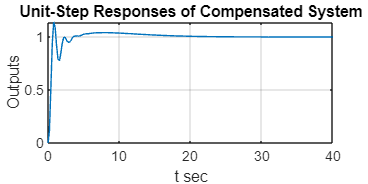


% Gc(s) = ((s + 0.4)/(s + 4))*((s + 0.2)/(s + 0.02))
% non compensated Closed loop G(s) = 150/(s^3+ 8s^2 + 15s + 150)
num = 150;
den = [1 8 15 150];

% Compensated closed loop G(s) = (150s^2 + 90s + 12)/(s^5 + 12.02*s^4 + 47.24s^3 + 210.94s^2 + 91.2s + 12)
numc = [150 90 12];
denc = [1 12.02 47.24 210.94 91.2 12];

% unit-step response
clf
t = 0:0.2:40;
%[c1,x1,t] = step(num,den,t);
[c2,x2,t] = step(numc,denc,t);
plot(t,c2,'-')
xlabel('t sec')
ylabel('Outputs')
%legend('uncompensated closed loop','compensated closed loop')
grid on
title('Unit-Step Responses of Compensated System')

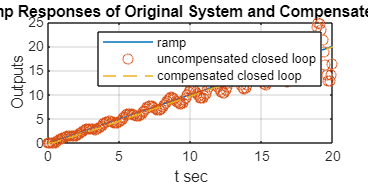


% unit-ramp response
clf
t = 0:0.1:20;
r = t;
c1 = lsim(num,den,r,t); % simulate a ramp
c2 = lsim(numc,denc,r,t);
plot(t,r,'-',t,c1,'o',t,c2,'--')
grid on
title('unit ramp response')
xlabel('t sec')
ylabel('Outputs')
legend('ramp','uncompensated closed loop','compensated closed loop')
title('Unit-ramp Responses of Original System and Compensated System')

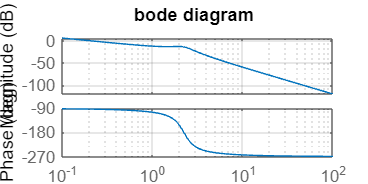

% 3.36 find possible value K for stability and phase margin of 50 degree

% Open loop transfer function G(s) = 1/(s(s^2+s+5))

num = [1];
den = [1 1 5 0];
[w,Gain,phase] = bode(num,den);

grid on

title('bode diagram')

G = tf(num,den)

G =
 
         1
  ---------------
  s^3 + s^2 + 5 s
 
Continuous-time transfer function.
Model Properties


[Gm, Pm, Wcg, Wcp] = margin(G)

Gm = 5.0000

Pm = 87.6737

Wcg = 2.2361

Wcp = 0.2015


% for a phase margin = 50 degree occures at w = 1.06. The gain = -7dB 
% so to have desired phase margin, we do 20 log(K) = 7
K = 10^(7/20)

K = 2.2387

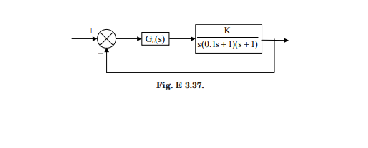

% 3.37 Design a lead compensator for a system where open loop transfer function G(s) = K/(s*(0.1s+1)*(s+1))
% Phase margin = 45 degree, gain margin higher than 8 dB and static
% velocity Kv = 4

% the closed loop representation

imshow(imread("closed_loop_12.png"));

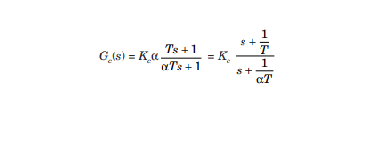


% The compensator form

imshow(imread("closed_loop_13.png"));

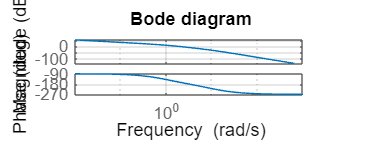


% we have Kv = lim s*Gc(s)*G(s) = Kc*alpha*K = 4
% for K = 1 we have alpha*Kc = 4

% bode of G(s) = 4/(s*(0.1s+1)*(s+1))


num = 4;
den = [0.1 1.1 1 0];
bode(num,den)
grid on
title('Bode diagram')

G = tf(num,den)

G =
 
            4
  ---------------------
  0.1 s^3 + 1.1 s^2 + s
 
Continuous-time transfer function.
Model Properties


[Gm, Pm, Wcg, Wcp] = margin(G)

Gm = 2.7500

Pm = 17.7051

Wcg = 3.1623

Wcp = 1.8612


% add lead compensator
%we have phase margin= 45 - 17 + 12 = 40degree
% We have sin(phase margin) = (1-alpha)/(1 + alpha) = 40 degree

phim = 40*pi/180;

alpha = (1 - sin(phim))/(1 + sin(phim))

alpha = 0.2174


% corner frequency w = 1/T
% other corner frequency is w = 1/(alpha*T) of lead compensator
% maximum phase-lead angle φm occurs at the geometric mean of the two
% corner or w = 1/(sqrt(alpha)*T) 
% at this frequency we have 
% |Gc(s)| = |((1+T*s)/(1 + alpha*T*s))| = 1/sqrt(alpha)

GdB  = 20*log10(1/sqrt(alpha))

GdB = 6.6265


% This gain corresponds to wc = 2.81 rad/s

wc = 2.81;

T = 1/(sqrt(alpha*wc))

T = 1.2793


Kc = 4/alpha

Kc = 18.3956

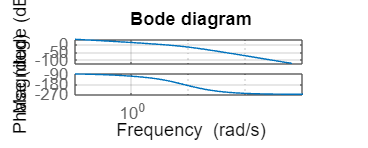


% we have so Gc(s) = 4*((0.7768s + 1)/(0.16308s + 1))

% The open loop transfer function is 
% Gc(s)*G(s) = 


% bode diagram for Gc(s)*G(s) = 4*((0.7768s + 1)/(0.16308s + 1))*(1/(s(0.1s + 1)(s + 1))

a = [0.16308 1];
b = [0.1 1.1 1 0];

num = [4*0.7768 4];
den = conv(a,b);
bode(num,den)
grid on
title('Bode diagram')

Gd = tf(num,den)

Gd =
 
                3.107 s + 4
  ----------------------------------------
  0.01631 s^4 + 0.2794 s^3 + 1.263 s^2 + s
 
Continuous-time transfer function.
Model Properties


[Gm, Pm, Wcg, Wcp] = margin(Gd)

Gm = 4.7842

Pm = 44.5889

Wcg = 7.5357

Wcp = 2.8161

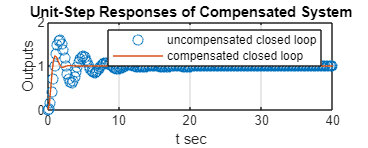


% Gc(s) = ((s + 0.4)/(s + 4))*((s + 0.2)/(s + 0.02))
% non compensated Closed loop G(s) = 4/(0.1s^3+ 1.1s^2 + s)
num = 4;
den = [0.1 1.1 1 4];

% Compensated closed loop Gc(s)*G(s)
numc = [3.107 4];
denc = [0.011631 0.2794 1.263 4.107 4];

% unit-step response
clf
t = 0:0.2:40;
[c1,x1,t] = step(num,den,t);
[c2,x2,t] = step(numc,denc,t);
plot(t,c1,'o',t,c2,'-')
xlabel('t sec')
ylabel('Outputs')
legend('uncompensated closed loop','compensated closed loop')
grid on
title('Unit-Step Responses of Compensated System')

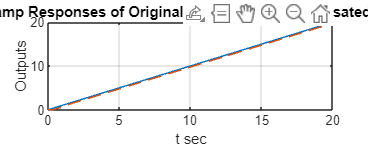


% unit-ramp response
clf
t = 0:0.1:20;
r = t;
% c1 = lsim(num,den,r,t); % simulate a ramp
c2 = lsim(numc,denc,r,t);
plot(t,r,'-',t,c2,'--')
grid on
title('unit ramp response')
xlabel('t sec')
ylabel('Outputs')
%legend('ramp','uncompensated closed loop','compensated closed loop')
title('Unit-ramp Responses of Original System and Compensated System')

% 3.38 state representation 

A = [0 1 0 0; 0 0 1 0; 0 0 0 1; -0.0069 -0.0789 -0.5784 -1.3852]

A =          0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000
   -0.0069   -0.0789   -0.5784   -1.3852


B = [0 0 0 2]'

B =      0
     0
     0
     2


C = [1 0 0 0]

C =      1     0     0     0


D = 0

D = 0

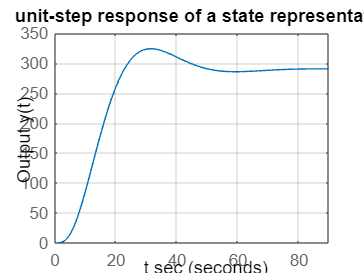

step(A,B,C,D);
grid on
xlabel('t sec')
ylabel('Output y(t)')
title('unit-step response of a state representation');

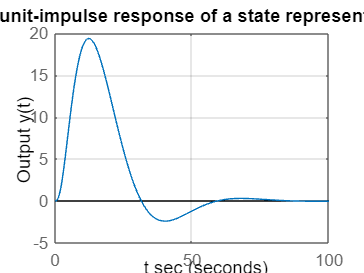


impulse(A,B,C,D);
grid on
xlabel('t sec')
ylabel('Output y(t)')
title('unit-impulse response of a state representation');

%  3.39 state representation from a transfer function

num = [0 0 35 7];
den = [1 5 36 7];
g = tf(num,den)

g =
 
         35 s + 7
  ----------------------
  s^3 + 5 s^2 + 36 s + 7
 
Continuous-time transfer function.
Model Properties


[A,B,C,D] = tf2ss(num,den)

A =     -5   -36    -7
     1     0     0
     0     1     0


B =      1
     0
     0


C =      0    35     7


D = 0

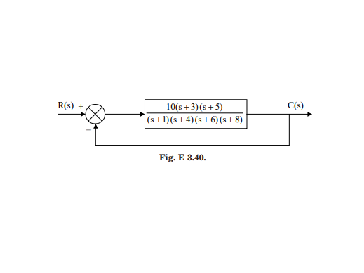

% 3.40 state response from a block diagram system

imshow(imread("closed_loop_14.png"));


'G(s)'

ans = 'G(s)'

G = zpk([-3 -5],[-1 -4 -6 -8],10)

G =
 
      10 (s+3) (s+5)
  -----------------------
  (s+1) (s+4) (s+6) (s+8)
 
Continuous-time zero/pole/gain model.
Model Properties



'T(s)'

ans = 'T(s)'

T = feedback(G, 1, -1)

T =
 
               10 (s+5) (s+3)
  -----------------------------------------
  (s+1.69) (s+4.425) (s^2 + 12.88s + 45.73)
 
Continuous-time zero/pole/gain model.
Model Properties


[numt,dent] = tfdata(T,'V');

'Controller cannonical form determination'

ans = 'Controller cannonical form determination'

[AC, BC, CC, DC] = tf2ss(numt,dent)

AC =   -19.0000 -132.0000 -376.0000 -342.0000
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


BC =      1
     0
     0
     0


CC =      0    10    80   150


DC = 0

A1 = flipud(AC);

'Phase variable form representation'

ans = 'Phase variable form representation'

Apv = fliplr(A1)

Apv =          0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000
 -342.0000 -376.0000 -132.0000  -19.0000


Bpv = flipud(BC)

Bpv =      0
     0
     0
     1


Cpv = fliplr(CC)

Cpv =    150    80    10     0



'Modal form'

ans = 'Modal form'

[A,B,C,D] = canon(AC,BC,CC,DC,'modal')

A =    -6.4425    2.0551         0         0
   -2.0551   -6.4425         0         0
         0         0   -4.4249         0
         0         0         0   -1.6902


B =   -33.9369
  -47.3120
   38.4290
    3.6509


C =    -0.0343    0.0448    0.0094    0.1620


D = 0

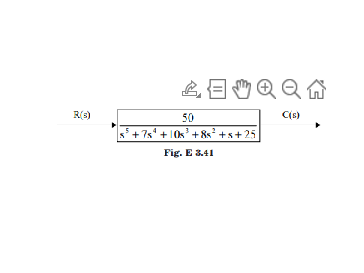

% 3.41 state response from a block diagram system

imshow(imread("closed_loop_15.png"));


'G(s)'

ans = 'G(s)'

num = 50;
den = [1 7 10 8 1 25];
G = tf(num,den)

G =
 
                   50
  -------------------------------------
  s^5 + 7 s^4 + 10 s^3 + 8 s^2 + s + 25
 
Continuous-time transfer function.
Model Properties



'Controller cannonical form determination'

ans = 'Controller cannonical form determination'

[AC, BC, CC, DC] = tf2ss(num,den);
A1 = flipud(AC)

A1 =      0     0     0     1     0
     0     0     1     0     0
     0     1     0     0     0
     1     0     0     0     0
    -7   -10    -8    -1   -25



'Phase variable form representation'

ans = 'Phase variable form representation'

Apv = fliplr(A1)

Apv =      0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1
   -25    -1    -8   -10    -7


Bpv = flipud(BC)

Bpv =      0
     0
     0
     0
     1


Cpv = fliplr(CC)

Cpv =     50     0     0     0     0



'Modal form'

ans = 'Modal form'

[A,B,C,D] = canon(AC,BC,CC,DC,'modal')

A =    -5.4585         0         0         0         0
         0   -1.3648    1.2919         0         0
         0   -1.2919   -1.3648         0         0
         0         0         0    0.5940    0.9716
         0         0         0   -0.9716    0.5940


B =     6.5063
    2.8825
   -3.0011
    1.2699
    0.1061


C =     0.0111   -0.0334   -0.3631   -0.7728   -0.7951


D = 0

% 3.42 state response from a block diagram system

imshow(imread("closed_loop_16.png"));

'Solution a'

ans = 'Solution a'


'G(s)'

ans = 'G(s)'

numa = [5 7];
dena = [1 7 3 9 8];
Ga = tf(numa,dena)

Ga =
 
             5 s + 7
  -----------------------------
  s^4 + 7 s^3 + 3 s^2 + 9 s + 8
 
Continuous-time transfer function.
Model Properties



'Controller cannonical form determination'

ans = 'Controller cannonical form determination'

[AC, BC, CC, DC] = tf2ss(numa,dena);
A1 = flipud(AC)

A1 =      0     0     1     0
     0     1     0     0
     1     0     0     0
    -7    -3    -9    -8



'Phase variable form representation'

ans = 'Phase variable form representation'

Apva = fliplr(A1)

Apva =      0     1     0     0
     0     0     1     0
     0     0     0     1
    -8    -9    -3    -7


Bpva = flipud(BC)

Bpva =      0
     0
     0
     1


Cpva = fliplr(CC)

Cpva =      7     5     0     0



'Modal form'

ans = 'Modal form'

[Aa,Ba,Ca,Da] = canon(AC,BC,CC,DC,'modal')

Aa =    -6.7266         0         0         0
         0    0.2485    1.2175         0
         0   -1.2175    0.2485         0
         0         0         0   -0.7703


Ba =     2.3787
    0.9778
   -0.3955
    0.7459


Ca =     0.0375   -0.5068   -0.4971    0.2812


Da = 0


'Solution b'

ans = 'Solution b'


'G(s)'

ans = 'G(s)'

numb = [1 3 12 7 8];
denb = [1 9 5 7 0 0];
Gb = tf(numb,denb)

Gb =
 
  s^4 + 3 s^3 + 12 s^2 + 7 s + 8
  ------------------------------
   s^5 + 9 s^4 + 5 s^3 + 7 s^2
 
Continuous-time transfer function.
Model Properties



'Controller cannonical form determination'

ans = 'Controller cannonical form determination'

[AC, BC, CC, DC] = tf2ss(numb,denb);
A1 = flipud(AC)

A1 =      0     0     0     1     0
     0     0     1     0     0
     0     1     0     0     0
     1     0     0     0     0
    -9    -5    -7     0     0



'Phase variable form representation'

ans = 'Phase variable form representation'

Apvb = fliplr(A1)

Apvb =      0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1
     0     0    -7    -5    -9


Bpvb = flipud(BC)

Bpvb =      0
     0
     0
     0
     1


Cpvb = fliplr(CC)

Cpvb =      8     7    12     3     1



'Modal form'

ans = 'Modal form'

[Ab,Bb,Cb,Db] = canon(AC,BC,CC,DC,'modal')

Ab =          0    0.5000         0         0         0
         0         0         0         0         0
         0         0   -8.5091         0         0
         0         0         0   -0.2455    0.8732
         0         0         0   -0.8732   -0.2455


Bb =    -0.8163
    2.2857
    4.6405
   -1.1189
    2.4862


Cb =     1.0000    0.4375    0.1815    0.0110   -0.0055


Db = 0

% 3.43 transfer function from state representation 

A = [0 1 0 ; -5 -2 0; 0 2 -6];
B = [0 0; 3 -1; 5 0]; % MIMO
C = [1 0 0; 0 0 1];
D = [0 0;0 0];

% G(s) = C* (sI - A)^-1 * B
syms s

M = s*[1 0 0;0 1 0;0 0 1] - A;

G = C*inv(M)*B

$$G = \left(\begin{array}{cc} \frac{3}{s^{2}+2\,s+5} & -\frac{1}{s^{2}+2\,s+5}\\ \frac{5}{s+6}+\frac{6\,s}{s^{3}+8\,s^{2}+17\,s+30} & -\frac{2\,s}{s^{3}+8\,s^{2}+17\,s+30} \end{array}\right)$$

% 3.44 transfer function from state representation 

A = [-4 -1 ; 2 -3];
B = [1;3];
C = [1 2];
D = 0;

% G(s) = C* (sI - A)^-1 * B
syms s

M = s*[1 0 ;0 1] - A;

G = C*inv(M)*B

$$G = \frac{1}{s^{2}+7\,s+14}+\frac{s+3}{s^{2}+7\,s+14}+\frac{6\,\left(s+4\right)}{s^{2}+7\,s+14}$$

% 3.45 transfer function from state representation 

A = [0 3 7 0; 0 0 1 0; 0 0 0 1; -5 -6 9 5];
B = [0 5 7 2]';
C = [1 3 6 5];
D = 0;

[numg,deng] = ss2tf(A,B,C,D,1);

G = tf(numg,deng)

G =
 
  67 s^3 - 23 s^2 - 2509 s - 894
  -------------------------------
  s^4 - 5 s^3 - 9 s^2 + 41 s + 15
 
Continuous-time transfer function.
Model Properties


% 3.46 transfer function from state representation 

A = [9 -3 -1; -3 2 0; 6 8 -2];
B = [1 2 3]';
C = [2 9 -12];
D = 0;

[numg,deng] = ss2tf(A,B,C,D,1);

G = tf(numg,deng)

G =
 
  -16 s^2 - 39 s + 2027
  ----------------------
  s^3 - 9 s^2 - 7 s - 18
 
Continuous-time transfer function.
Model Properties



% Poles of transfer function
roots(deng)

ans =    9.8916 + 0.0000i
  -0.4458 + 1.2732i
  -0.4458 - 1.2732i


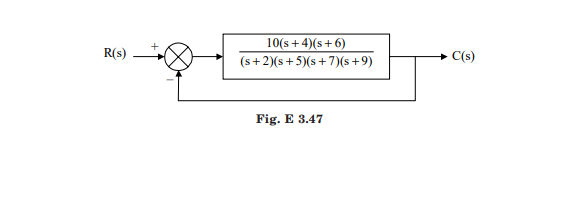

% 3.47 state response from a feedback block diagram system

imshow(imread("closed_loop_17.png"));


'Phase variable form'

ans = 'Phase variable form'

    
'G(s)'

ans = 'G(s)'

G = zpk([-4 -6],[-2 -5 -7 -9],10)

G =
 
      10 (s+4) (s+6)
  -----------------------
  (s+2) (s+5) (s+7) (s+9)
 
Continuous-time zero/pole/gain model.
Model Properties



'T(s)'

ans = 'T(s)'

T = feedback(G,1,-1)

T =
 
               10 (s+6) (s+4)
  -----------------------------------------
  (s+2.69) (s+5.425) (s^2 + 14.88s + 59.61)
 
Continuous-time zero/pole/gain model.
Model Properties



[numt,dent] = tfdata(T,'V');

'Controller cannonical form determination'

ans = 'Controller cannonical form determination'

[AC, BC, CC, DC] = tf2ss(numt,dent)

AC =   -23.0000 -195.0000 -701.0000 -870.0000
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


BC =      1
     0
     0
     0


CC =          0   10.0000  100.0000  240.0000


DC = 0

A1 = flipud(AC);

'Phase variable form representation'

ans = 'Phase variable form representation'

Apva = fliplr(A1)

Apva =          0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000
 -870.0000 -701.0000 -195.0000  -23.0000


Bpva = flipud(BC)

Bpva =      0
     0
     0
     1


Cpva = fliplr(CC)

Cpva =   240.0000  100.0000   10.0000         0




'Modal form'

ans = 'Modal form'

[A,B,C,D] = canon(AC,BC,CC,DC,'modal')

A =    -7.4425    2.0551         0         0
   -2.0551   -7.4425         0         0
         0         0   -5.4249         0
         0         0         0   -2.6902


B =   -47.3583
  -59.0710
   54.6502
    6.6721


C =    -0.0245    0.0358    0.0066    0.0886


D = 0

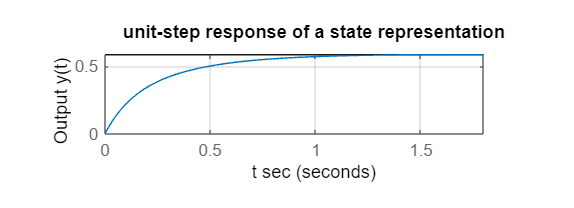

% 3.48 unit step response from state representation 

A = [-5 2 0; 0 -9 1; 0 0 -3];
B = [0 2 1]';
C = [0 1 1];
D = 0;
step(A,B,C,D);
grid on
xlabel('t sec')
ylabel('Output y(t)')
title('unit-step response of a state representation');

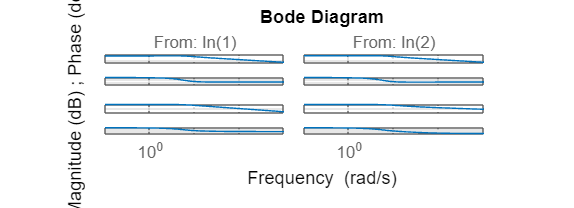

% 3.49 Bode diagram from state representation 

A = [0  1; -30 -7];
B = [1 1; 0 1];
C = [1 0; 0 1];
D = [0 0; 0 0];
bode(A,B,C,D)
grid on

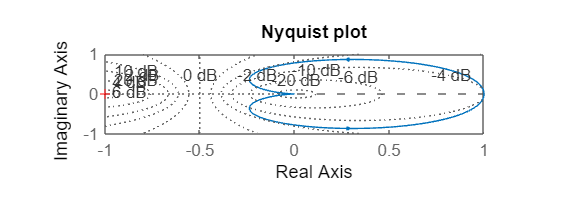

% 3.50 Nyquist diagram from state representation 

A = [0  1; -30 7];
B = [0 30]';
C = [1 0];
D = 0;
nyquist(A,B,C,D)
grid on
title("Nyquist plot")

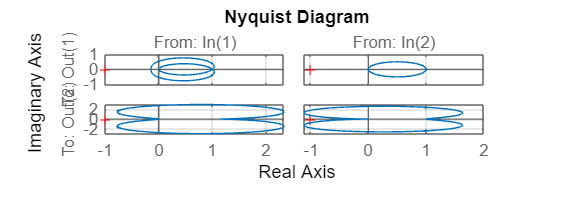

% 3.51 Nyquist diagram from state representation MIMO

A = [-1 -1;7 0];
B = [1 1;1 0];
C = [1 0;0 1];
D = [0 0; 0 0];
nyquist(A,B,C,D)
grid on

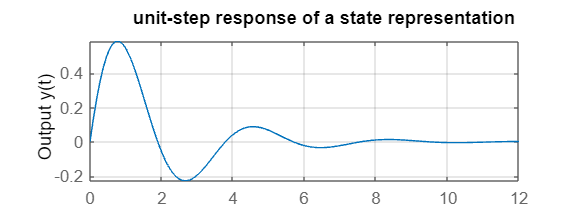

% 3.52 Responses from state representation

A = [-1 -1.5;2 0];
B = [1.5 0]';
C = [1 0];
D = 0;
step(A,B,C,D);
grid on
xlabel('t sec')
ylabel('Output y(t)')
title('unit-step response of a state representation');

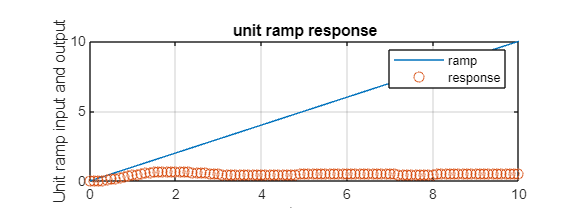

t = 0:0.1:10;
r = t;
y = lsim(A,B,C,D,r,t); % simulate a ramp
plot(t,r,'-',t,y,'o')
grid
title('unit ramp response')
xlabel('t sec')
ylabel('Unit ramp input and output')
legend('ramp','response')

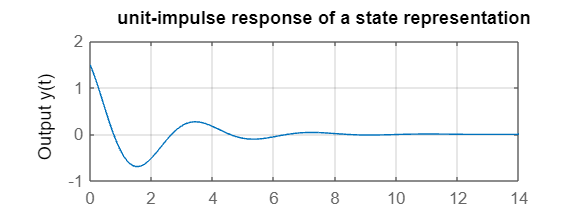

impulse(A,B,C,D);
grid on
xlabel('t sec')
ylabel('Output y(t)')
title('unit-impulse response of a state representation');

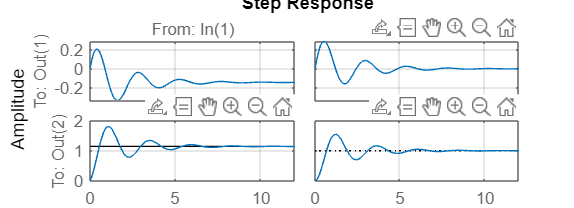

% 3.53 unit step Responses from state representation

A = [-1 -1;7 0];
B = [1 1;1 0];
C = [1 0;0 1];
D = [0 0;0 0];
step(A,B,C,D)
grid on;

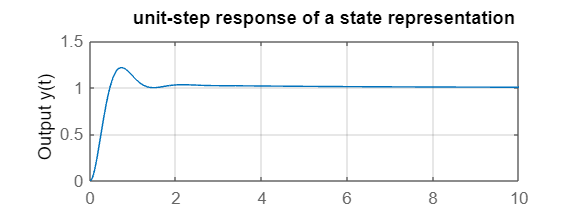

% 3.54 Responses from state representation 

A = [-5 -25 -5;1 0 0; 0 1 0];
B = [1 0 0]';
C = [0 25 5];
D = 0;
step(A,B,C,D);
grid on
xlabel('t sec')
ylabel('Output y(t)')
title('unit-step response of a state representation');

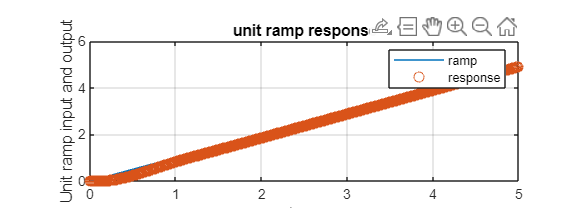

t = 0:0.01:5;
r = t;
y = lsim(A,B,C,D,r,t); % simulate a ramp
plot(t,r,'-',t,y,'o')
grid
title('unit ramp response')
xlabel('t sec')
ylabel('Unit ramp input and output')
legend('ramp','response')

% 3.55 Controllability and observability of a system from its state space
% representation MIMO

A = [3 0 0; 0 1 0; 0 4 5];
B = [0 2; 2 0; 0 1];
C = [1 2 0; 0 1 0];
D = [0 0;0 0];

rank([B A*B A^2*B])

ans = 3


rank([C' A'*C' A^2'*C'])

ans = 2


rank([C*B C*A*B C*A^2*B])

ans = 2


% We observe that system is controllable but not completely observable

% 3.56 observability of a system from its state space representation

A = [3 0 0; 0 1 0; 0 3 2];
C = [1 1 1];

rank([C' A'*C' A^2'*C'])

ans = 3


% We observe that system is observable

% observability of a system from its state space representation MIMO
A = [3 0 0; 0 1 0; 0 3 2];
C = [1 1 1; 1 3 2];

rank([C' A'*C' A^2'*C'])

ans = 3

% We observe that system is observable

% 3.57 Controllability and observability of a system from its state space representation

A = [-1 -3 -2; 0 -2 1; 1 0 -1];
B = [3 0 1]';
C = [1 1 0];

rank([B A*B A^2*B])

ans = 3

% We observe that the system is completely controllable

rank([C' A'*C' A^2'*C'])

ans = 3

% We observe that the system is completely observable

% Diagonalization of a system from its state representation

A = [-7 -5 5; 15 6 -12; -8 -3 4];
B = [-1 4 2]';
C = [1 -3 5];
[P,D] = eig(A);

Ad = inv(P)*A*P

Ad =    2.4555 + 6.0296i  -0.0000 + 0.0000i   0.0000 - 0.0000i
  -0.0000 - 0.0000i   2.4555 - 6.0296i   0.0000 + 0.0000i
   0.0000 - 0.0000i   0.0000 + 0.0000i  -1.9110 + 0.0000i


Bd = inv(P)*B

Bd =    1.8397 + 2.1026i
   1.8397 - 2.1026i
   3.3254 - 0.0000i


Cd = inv(P)*C'

Cd =   -2.4324 + 5.4360i
  -2.4324 - 5.4360i
   2.6093 + 0.0000i


% 3.59 Eigenvalues of a system from its state representation

A = [0 2 0;0 2 -9; -2 2 5];
B = [0 0 2]';
C = [0 0 1];
eig(A)

ans =    2.0000 + 0.0000i
   2.5000 + 3.4278i
   2.5000 - 3.4278i


% 3.60 Determination of stability of a unity feedback system in state space
% representation using Routh-Hurwitz criterion

A = [0 2 0; 0 1 9; -2 -4 -6];
B =  [0 0 2]';
C = [0 1 1];
D = 0;
'G';
G = ss(A,B,C,D); % creation of state-space model
'T';
T = feedback(G,1);
'eigenvalues of T are'

ans = 'eigenvalues of T are'

ssdata(T);
eig(T)

ans =   -0.8872 + 0.0000i
  -3.0564 + 5.5888i
  -3.0564 - 5.5888i



% the closed loop system is stable as the real part of eigenvalue of unit
% feedback system are all negative using Routh-Hurwitz criterion

% 3.61 Determination of stability of a unity feedback system in state space
% representation using Routh-Hurwitz criterion

A = [0 1 0; 0 1 7; -3 -4 -6];
B =  [0 0 2]';
C = [0 1 1];
D = 0;
'G';
G = ss(A,B,C,D); % creation of state-space model
'T';
T = feedback(G,1);
'eigenvalues of T are'

ans = 'eigenvalues of T are'

ssdata(T);
eig(T)

ans =   -0.7112 + 0.0000i
  -3.1444 + 4.4317i
  -3.1444 - 4.4317i



% the closed loop system is stable as the real part of eigenvalue of unit
% feedback system are all negative using Routh-Hurwitz criterion

15.08+4.02*8

ans = 47.2400

4.02*15+0.08*8

ans = 60.9400

4.02*15+0.08*8+150

ans = 210.9400

15*0.08+0.6*150

ans = 91.2000

150*0.08

ans = 12

function c = Veccrossproduct(a,b)
    % 2.4 Function to compute cross product of two vectors
    c = [a(2)*b(3) - a(3)*b(2);-(a(1)*b(3) - a(3)*b(1));a(1)*b(2) - a(2)*b(1)];
end

